% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

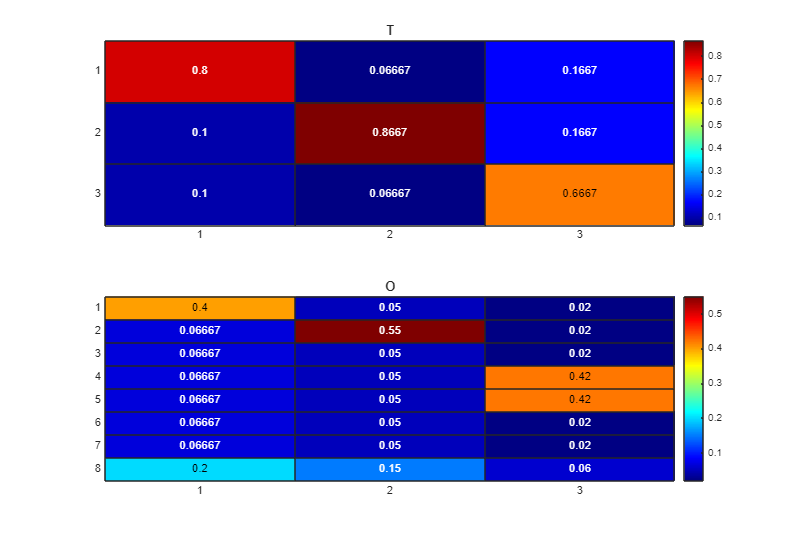

k = 5;
d = 20;

options.method = "standard";
options.lambda = 2;

[T, O, pi, k, d] = generateHMM(k, d, 1, options);

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(2, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(2, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

eig(T)

ans =     1.0000
    0.7549
    0.5785


Generate an observational sequence based on the defined HMM

T_seq = 1e5;

[seq,states] = hmmgenerate(T_seq,T',O');

% U{1} = (O' * T);
% U{2} = O';
% U{3} = (O' * T');
% 
% P3 = cpdgen(U);
% 
% [V, D, W] = eig(T);
% mu = abs(W(:, 1));
% mu = mu ./ sum(mu);
% P2 = O' * T * diag(mu) * O;

Generate Probability Density Tensors

tic
P3 = ProbabilityTensorGenerate(seq, 3, d);
P2 = ProbabilityTensorGenerate(seq, 2, d);
toc

Elapsed time is 0.938885 seconds.




warning('off', 'all')

rho = 0: 0.1 : 1;
iter = 1:length(rho);

max_iters = 1000;

Cost = zeros(1, length(iter));

for i = progress(iter)
    options.maxiter = 100;
    options.th_relerr = 1e-6;
    options.rho = rho(i);

    [B1, B2, B3, B4, c, output] = cpd_als_3d_regularized(P3, P2, k, options);
    % [B1, B2, B3, B4] = als_tensor_factorization(P3, P2, k, rho(i), max_iters);

    % Cost(i) = output.relerr(end);
end

Processing:  000%  |                                        | 0/11it [00:00:00<Inf:NaN:NaN, Inf it/s]

ans =    10.1547   -7.0512  -14.6743
   -7.0512  176.0527  -36.6230
  -14.6743  -36.6230  119.8226


ans =     8.7393  -10.4736   -8.4871
  -10.4736  199.1448  -29.0521
   -8.4871  -29.0521  109.6612


ans =     8.6912  -12.7220   -7.5168
  -12.7220  224.5851  -25.5610
   -7.5168  -25.5610  117.6774


ans =     8.9748  -14.5996   -7.9162
  -14.5996  246.8366  -23.7038
   -7.9162  -23.7038  129.0148


ans =     9.2405  -16.0342   -8.4705
  -16.0342  263.5992  -22.5281
   -8.4705  -22.5281  138.8149


ans =     9.4300  -17.0611   -8.9109
  -17.0611  275.4622  -21.6430
   -8.9109  -21.6430  146.2548


ans =     9.5566  -17.7836   -9.2208
  -17.7836  283.7328  -20.9305
   -9.2208  -20.9305  151.6633


ans =     9.6403  -18.2915   -9.4309
  -18.2915  289.4996  -20.3586
   -9.4309  -20.3586  155.5308


ans =     9.6960  -18.6497   -9.5720
  -18.6497  293.5365  -19.9107
   -9.5720  -19.9107  158.2790


ans =     9.7334  -18.9028   -9.6669
  -18.9028  296.3737  -19.5687
   -9.6669  -19.5687  160.2279


ans =     9.7589  -19.0819   -9.7313
  -19.0819  298.3742  -19.3130
   -9.7313  -19.3130  161.6096


ans =     9.7764  -19.2088   -9.7753
  -19.2088  299.7882  -19.1246
   -9.7753  -19.1246  162.5894


ans =     9.7884  -19.2988   -9.8057
  -19.2988  300.7893  -18.9873
   -9.8057  -18.9873  163.2847


ans =     9.7969  -19.3626   -9.8267
  -19.3626  301.4992  -18.8880
   -9.8267  -18.8880  163.7784


ans =     9.8028  -19.4080   -9.8414
  -19.4080  302.0030  -18.8165
   -9.8414  -18.8165  164.1291


ans =     9.8069  -19.4402   -9.8518
  -19.4402  302.3608  -18.7652
   -9.8518  -18.7652  164.3783


ans =     9.8098  -19.4631   -9.8590
  -19.4631  302.6150  -18.7286
   -9.8590  -18.7286  164.5554


ans =     9.8119  -19.4794   -9.8642
  -19.4794  302.7958  -18.7024
   -9.8642  -18.7024  164.6814


ans =     9.8134  -19.4909   -9.8678
  -19.4909  302.9243  -18.6837
   -9.8678  -18.6837  164.7710


ans =     9.8144  -19.4992   -9.8704
  -19.4992  303.0157  -18.6703
   -9.8704  -18.6703  164.8347


ans =     9.8152  -19.5050   -9.8722
  -19.5050  303.0807  -18.6608
   -9.8722  -18.6608  164.8801


ans =     9.8157  -19.5092   -9.8735
  -19.5092  303.1270  -18.6541
   -9.8735  -18.6541  164.9123


ans =     9.8161  -19.5122   -9.8744
  -19.5122  303.1599  -18.6493
   -9.8744  -18.6493  164.9353


ans =     9.8163  -19.5143   -9.8751
  -19.5143  303.1833  -18.6458
   -9.8751  -18.6458  164.9516


ans =     9.8165  -19.5158   -9.8755
  -19.5158  303.2000  -18.6434
   -9.8755  -18.6434  164.9632


ans =     9.8166  -19.5168   -9.8759
  -19.5168  303.2118  -18.6417
   -9.8759  -18.6417  164.9715


ans =     9.8167  -19.5176   -9.8761
  -19.5176  303.2203  -18.6404
   -9.8761  -18.6404  164.9774


ans =     9.8168  -19.5181   -9.8763
  -19.5181  303.2263  -18.6396
   -9.8763  -18.6396  164.9815


ans =     9.8169  -19.5185   -9.8764
  -19.5185  303.2305  -18.6389
   -9.8764  -18.6389  164.9845


ans =     9.8169  -19.5188   -9.8765
  -19.5188  303.2336  -18.6385
   -9.8765  -18.6385  164.9866


ans =     9.8169  -19.5190   -9.8765
  -19.5190  303.2357  -18.6382
   -9.8765  -18.6382  164.9881


ans =     9.8169  -19.5191   -9.8766
  -19.5191  303.2373  -18.6379
   -9.8766  -18.6379  164.9892


ans =     9.8169  -19.5192   -9.8766
  -19.5192  303.2384  -18.6378
   -9.8766  -18.6378  164.9900


ans =     9.8169  -19.5193   -9.8766
  -19.5193  303.2391  -18.6377
   -9.8766  -18.6377  164.9905


ans =     9.8170  -19.5193   -9.8766
  -19.5193  303.2397  -18.6376
   -9.8766  -18.6376  164.9909


ans =     9.8170  -19.5194   -9.8767
  -19.5194  303.2401  -18.6375
   -9.8767  -18.6375  164.9912


ans =     9.8170  -19.5194   -9.8767
  -19.5194  303.2404  -18.6375
   -9.8767  -18.6375  164.9914


ans =     9.8170  -19.5194   -9.8767
  -19.5194  303.2406  -18.6375
   -9.8767  -18.6375  164.9915


ans =     9.8170  -19.5194   -9.8767
  -19.5194  303.2407  -18.6374
   -9.8767  -18.6374  164.9916


ans =     9.8170  -19.5194   -9.8767
  -19.5194  303.2408  -18.6374
   -9.8767  -18.6374  164.9917


ans =     9.8170  -19.5194   -9.8767
  -19.5194  303.2409  -18.6374
   -9.8767  -18.6374  164.9917


ans =     9.8170  -19.5194   -9.8767
  -19.5194  303.2409  -18.6374
   -9.8767  -18.6374  164.9918


ans =     9.8170  -19.5195   -9.8767
  -19.5195  303.2410  -18.6374
   -9.8767  -18.6374  164.9918


ans =     9.8170  -19.5195   -9.8767
  -19.5195  303.2410  -18.6374
   -9.8767  -18.6374  164.9918


ans =     9.8170  -19.5195   -9.8767
  -19.5195  303.2410  -18.6374
   -9.8767  -18.6374  164.9918


ans =     9.8170  -19.5195   -9.8767
  -19.5195  303.2410  -18.6374
   -9.8767  -18.6374  164.9918


ans =     9.8170  -19.5195   -9.8767
  -19.5195  303.2410  -18.6374
   -9.8767  -18.6374  164.9918


ans =     9.8170  -19.5195   -9.8767
  -19.5195  303.2410  -18.6374
   -9.8767  -18.6374  164.9918


ans =     9.8170  -19.5195   -9.8767
  -19.5195  303.2410  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2410  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2410  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
    9.8170  -19.5195   -9.8767
  -19.5195  303.2411  -18.6374
   -9.8767  -18.6374  164.9919


ans = 3×3
  113.7751  -15.5117  -49.9457
  -15.5117   17.9654   -6.0455
  -49.9457   -6.0455   89.3118


ans = 3×3
   88.1281  -15.1361  -27.1149
  -15.1361   17.7094   -5.8624
  -27.1149   -5.8624   72.2343


ans = 3×3
   80.3257  -14.8417  -20.0046
  -14.8417   16.7525   -4.4538
  -20.0046   -4.4538   65.5228


ans = 3×3
   74.9940  -13.7543  -17.2113
  -13.7543   15.9923   -3.9839
  -17.2113   -3.9839   64.6265


ans = 3×3
   72.0439  -12.8280  -16.4105
  -12.8280   15.4376   -3.7027
  -16.4105   -3.7027   65.5377


ans = 3×3
   70.4524  -12.2121  -16.3487
  -12.2121   15.0603   -3.4478
  -16.3487   -3.4478   66.7340


ans = 3×3
   69.5316  -11.8202  -16.4772
  -11.8202   14.8078   -3.2285
  -16.4772   -3.2285   67.7444


ans = 3×3
   68.9489  -11.5711  -16.6107
  -11.5711   14.6405   -3.0558
  -16.6107   -3.0558   68.4838


ans = 3×3
   68.5530  -11.4113  -16.7056
  -11.4113   14.5309   -2.9276
  -16.7056   -2.9276   68.9862


ans = 3×3
   68.2719  -11.3079  -16.7634
  -11.3079   14.4604   -2.8358
  -16.7634   -2.8358   69.3104


ans = 3×3
   68.0669  -11.2409  -16.7948
  -11.2409   14.4161   -2.7714
  -16.7948   -2.7714   69.5091


ans = 3×3
   67.9144  -11.1973  -16.8093
  -11.1973   14.3895   -2.7267
  -16.8093   -2.7267   69.6224


ans = 3×3
   67.7990  -11.1691  -16.8137
  -11.1691   14.3748   -2.6960
  -16.8137   -2.6960   69.6780


ans = 3×3
   67.7095  -11.1511  -16.8120
  -11.1511   14.3680   -2.6748
  -16.8120   -2.6748   69.6952


ans = 3×3
   67.6384  -11.1396  -16.8067
  -11.1396   14.3664   -2.6602
  -16.8067   -2.6602   69.6867


ans = 3×3
   67.5801  -11.1325  -16.7992
  -11.1325   14.3684   -2.6502
  -16.7992   -2.6502   69.6609


ans = 3×3
   67.5307  -11.1282  -16.7904
  -11.1282   14.3727   -2.6432
  -16.7904   -2.6432   69.6237


ans = 3×3
   67.4875  -11.1258  -16.7807
  -11.1258   14.3785   -2.6383
  -16.7807   -2.6383   69.5787


ans = 3×3
   67.4487  -11.1246  -16.7706
  -11.1246   14.3853   -2.6348
  -16.7706   -2.6348   69.5285


ans = 3×3
   67.4129  -11.1242  -16.7602
  -11.1242   14.3928   -2.6324
  -16.7602   -2.6324   69.4748


ans = 3×3
   67.3792  -11.1243  -16.7495
  -11.1243   14.4008   -2.6305
  -16.7495   -2.6305   69.4188


ans = 3×3
   67.3470  -11.1247  -16.7387
  -11.1247   14.4091   -2.6292
  -16.7387   -2.6292   69.3612


ans = 3×3
   67.3158  -11.1253  -16.7279
  -11.1253   14.4175   -2.6281
  -16.7279   -2.6281   69.3026


ans = 3×3
   67.2854  -11.1261  -16.7170
  -11.1261   14.4261   -2.6273
  -16.7170   -2.6273   69.2432


ans = 3×3
   67.2554  -11.1270  -16.7061
  -11.1270   14.4348   -2.6266
  -16.7061   -2.6266   69.1835


ans = 3×3
   67.2258  -11.1279  -16.6952
  -11.1279   14.4435   -2.6260
  -16.6952   -2.6260   69.1234


ans = 3×3
   67.1965  -11.1289  -16.6843
  -11.1289   14.4523   -2.6255
  -16.6843   -2.6255   69.0632


ans = 3×3
   67.1674  -11.1298  -16.6734
  -11.1298   14.4611   -2.6251
  -16.6734   -2.6251   69.0029


ans = 3×3
   67.1384  -11.1308  -16.6625
  -11.1308   14.4699   -2.6246
  -16.6625   -2.6246   68.9426


ans = 3×3
   67.1095  -11.1319  -16.6516
  -11.1319   14.4788   -2.6242
  -16.6516   -2.6242   68.8822


ans = 3×3
   67.0808  -11.1329  -16.6407
  -11.1329   14.4876   -2.6238
  -16.6407   -2.6238   68.8219


ans = 3×3
   67.0521  -11.1339  -16.6298
  -11.1339   14.4965   -2.6234
  -16.6298   -2.6234   68.7616


ans = 3×3
   67.0234  -11.1349  -16.6189
  -11.1349   14.5054   -2.6231
  -16.6189   -2.6231   68.7014


ans = 3×3
   66.9949  -11.1359  -16.6081
  -11.1359   14.5143   -2.6227
  -16.6081   -2.6227   68.6412


ans = 3×3
   66.9663  -11.1370  -16.5972
  -11.1370   14.5232   -2.6223
  -16.5972   -2.6223   68.5810


ans = 3×3
   66.9378  -11.1380  -16.5864
  -11.1380   14.5320   -2.6220
  -16.5864   -2.6220   68.5210


ans = 3×3
   66.9094  -11.1391  -16.5756
  -11.1391   14.5410   -2.6216
  -16.5756   -2.6216   68.4610


ans = 3×3
   66.8810  -11.1401  -16.5648
  -11.1401   14.5499   -2.6212
  -16.5648   -2.6212   68.4011


ans = 3×3
   66.8526  -11.1411  -16.5540
  -11.1411   14.5588   -2.6209
  -16.5540   -2.6209   68.3412


ans = 3×3
   66.8243  -11.1422  -16.5432
  -11.1422   14.5677   -2.6205
  -16.5432   -2.6205   68.2814


ans = 3×3
   66.7960  -11.1432  -16.5324
  -11.1432   14.5766   -2.6202
  -16.5324   -2.6202   68.2217


ans = 3×3
   66.7677  -11.1443  -16.5217
  -11.1443   14.5856   -2.6198
  -16.5217   -2.6198   68.1621


ans = 3×3
   66.7395  -11.1453  -16.5109
  -11.1453   14.5945   -2.6195
  -16.5109   -2.6195   68.1025


ans = 3×3
   66.7113  -11.1464  -16.5002
  -11.1464   14.6035   -2.6191
  -16.5002   -2.6191   68.0430


ans = 3×3
   66.6832  -11.1475  -16.4895
  -11.1475   14.6124   -2.6188
  -16.4895   -2.6188   67.9836


ans = 3×3
   66.6551  -11.1485  -16.4788
  -11.1485   14.6214   -2.6184
  -16.4788   -2.6184   67.9242


ans = 3×3
   66.6270  -11.1496  -16.4681
  -11.1496   14.6304   -2.6181
  -16.4681   -2.6181   67.8650


ans = 3×3
   66.5990  -11.1506  -16.4574
  -11.1506   14.6394   -2.6177
  -16.4574   -2.6177   67.8058


ans = 3×3
   66.5710  -11.1517  -16.4467
  -11.1517   14.6483   -2.6174
  -16.4467   -2.6174   67.7466


ans = 3×3
   66.5430  -11.1528  -16.4361
  -11.1528   14.6573   -2.6170
  -16.4361   -2.6170   67.6876


ans = 3×3
   66.5151  -11.1539  -16.4254
  -11.1539   14.6663   -2.6167
  -16.4254   -2.6167   67.6286


ans = 3×3
   66.4872  -11.1549  -16.4148
  -11.1549   14.6753   -2.6163
  -16.4148   -2.6163   67.5697


ans = 3×3
   66.4593  -11.1560  -16.4042
  -11.1560   14.6843   -2.6160
  -16.4042   -2.6160   67.5108


ans = 3×3
   66.4315  -11.1571  -16.3936
  -11.1571   14.6934   -2.6156
  -16.3936   -2.6156   67.4521


ans = 3×3
   66.4037  -11.1582  -16.3830
  -11.1582   14.7024   -2.6153
  -16.3830   -2.6153   67.3934


ans = 3×3
   66.3759  -11.1593  -16.3724
  -11.1593   14.7114   -2.6149
  -16.3724   -2.6149   67.3348


ans = 3×3
   66.3482  -11.1603  -16.3618
  -11.1603   14.7204   -2.6146
  -16.3618   -2.6146   67.2762


ans = 3×3
   66.3205  -11.1614  -16.3513
  -11.1614   14.7295   -2.6142
  -16.3513   -2.6142   67.2177


ans = 3×3
   66.2928  -11.1625  -16.3407
  -11.1625   14.7385   -2.6139
  -16.3407   -2.6139   67.1593


ans = 3×3
   66.2652  -11.1636  -16.3302
  -11.1636   14.7476   -2.6136
  -16.3302   -2.6136   67.1010


ans = 3×3
   66.2376  -11.1647  -16.3197
  -11.1647   14.7567   -2.6132
  -16.3197   -2.6132   67.0427


ans = 3×3
   66.2101  -11.1658  -16.3092
  -11.1658   14.7657   -2.6129
  -16.3092   -2.6129   66.9846


ans = 3×3
   66.1826  -11.1669  -16.2987
  -11.1669   14.7748   -2.6125
  -16.2987   -2.6125   66.9264


ans = 3×3
   66.1551  -11.1680  -16.2882
  -11.1680   14.7839   -2.6122
  -16.2882   -2.6122   66.8684


ans = 3×3
   66.1277  -11.1691  -16.2777
  -11.1691   14.7930   -2.6118
  -16.2777   -2.6118   66.8104


ans = 3×3
   66.1003  -11.1702  -16.2672
  -11.1702   14.8021   -2.6115
  -16.2672   -2.6115   66.7525


ans = 3×3
   66.0729  -11.1714  -16.2568
  -11.1714   14.8112   -2.6112
  -16.2568   -2.6112   66.6947


ans = 3×3
   66.0455  -11.1725  -16.2464
  -11.1725   14.8203   -2.6108
  -16.2464   -2.6108   66.6369


ans = 3×3
   66.0182  -11.1736  -16.2359
  -11.1736   14.8294   -2.6105
  -16.2359   -2.6105   66.5792


ans = 3×3
   65.9910  -11.1747  -16.2255
  -11.1747   14.8385   -2.6102
  -16.2255   -2.6102   66.5216


ans = 3×3
   65.9637  -11.1758  -16.2151
  -11.1758   14.8476   -2.6098
  -16.2151   -2.6098   66.4641


ans = 3×3
   65.9365  -11.1769  -16.2047
  -11.1769   14.8568   -2.6095
  -16.2047   -2.6095   66.4066


ans = 3×3
   65.9094  -11.1781  -16.1944
  -11.1781   14.8659   -2.6091
  -16.1944   -2.6091   66.3492


ans = 3×3
   65.8822  -11.1792  -16.1840
  -11.1792   14.8750   -2.6088
  -16.1840   -2.6088   66.2919


ans = 3×3
   65.8552  -11.1803  -16.1737
  -11.1803   14.8842   -2.6085
  -16.1737   -2.6085   66.2346


ans = 3×3
   65.8281  -11.1815  -16.1633
  -11.1815   14.8934   -2.6081
  -16.1633   -2.6081   66.1774


ans = 3×3
   65.8011  -11.1826  -16.1530
  -11.1826   14.9025   -2.6078
  -16.1530   -2.6078   66.1203


ans = 3×3
   65.7741  -11.1837  -16.1427
  -11.1837   14.9117   -2.6075
  -16.1427   -2.6075   66.0632


ans = 3×3
   65.7471  -11.1849  -16.1324
  -11.1849   14.9209   -2.6071
  -16.1324   -2.6071   66.0063


ans = 3×3
   65.7202  -11.1860  -16.1221
  -11.1860   14.9301   -2.6068
  -16.1221   -2.6068   65.9493


ans = 3×3
   65.6933  -11.1872  -16.1118
  -11.1872   14.9392   -2.6065
  -16.1118   -2.6065   65.8925


ans = 3×3
   65.6665  -11.1883  -16.1015
  -11.1883   14.9484   -2.6061
  -16.1015   -2.6061   65.8357


ans = 3×3
   65.6397  -11.1895  -16.0913
  -11.1895   14.9576   -2.6058
  -16.0913   -2.6058   65.7790


ans = 3×3
   65.6129  -11.1906  -16.0811
  -11.1906   14.9668   -2.6055
  -16.0811   -2.6055   65.7224


ans = 3×3
   65.5861  -11.1918  -16.0708
  -11.1918   14.9761   -2.6051
  -16.0708   -2.6051   65.6659


ans = 3×3
   65.5594  -11.1929  -16.0606
  -11.1929   14.9853   -2.6048
  -16.0606   -2.6048   65.6094


ans = 3×3
   65.5327  -11.1941  -16.0504
  -11.1941   14.9945   -2.6045
  -16.0504   -2.6045   65.5530


ans = 3×3
   65.5061  -11.1953  -16.0402
  -11.1953   15.0037   -2.6042
  -16.0402   -2.6042   65.4966


ans = 3×3
   65.4795  -11.1964  -16.0300
  -11.1964   15.0130   -2.6038
  -16.0300   -2.6038   65.4403


ans = 3×3
   65.4529  -11.1976  -16.0199
  -11.1976   15.0222   -2.6035
  -16.0199   -2.6035   65.3841


ans = 3×3
   65.4264  -11.1988  -16.0097
  -11.1988   15.0315   -2.6032
  -16.0097   -2.6032   65.3280


ans = 3×3
   65.3999  -11.1999  -15.9996
  -11.1999   15.0407   -2.6029
  -15.9996   -2.6029   65.2719


ans = 3×3
   65.3734  -11.2011  -15.9894
  -11.2011   15.0500   -2.6025
  -15.9894   -2.6025   65.2159


ans = 3×3
   65.3470  -11.2023  -15.9793
  -11.2023   15.0593   -2.6022
  -15.9793   -2.6022   65.1600


ans = 3×3
   65.3206  -11.2035  -15.9692
  -11.2035   15.0686   -2.6019
  -15.9692   -2.6019   65.1041


ans = 3×3
   65.2942  -11.2046  -15.9591
  -11.2046   15.0778   -2.6016
  -15.9591   -2.6016   65.0484


ans = 3×3
   65.2679  -11.2058  -15.9490
  -11.2058   15.0871   -2.6012
  -15.9490   -2.6012   64.9926


ans = 3×3
   65.2416  -11.2070  -15.9389
  -11.2070   15.0964   -2.6009
  -15.9389   -2.6009   64.9370


ans = 3×3
   65.2153  -11.2082  -15.9289
  -11.2082   15.1057   -2.6006
  -15.9289   -2.6006   64.8814


ans = 3×3
   65.1891  -11.2094  -15.9188
  -11.2094   15.1151   -2.6003
  -15.9188   -2.6003   64.8259


ans = 3×3
   65.1629  -11.2106  -15.9088
  -11.2106   15.1244   -2.5999
  -15.9088   -2.5999   64.7704


ans = 3×3
   65.1367  -11.2118  -15.8988
  -11.2118   15.1337   -2.5996
  -15.8988   -2.5996   64.7151


ans = 3×3
   65.1106  -11.2130  -15.8888
  -11.2130   15.1430   -2.5993
  -15.8888   -2.5993   64.6598


ans = 3×3
   65.0845  -11.2142  -15.8788
  -11.2142   15.1524   -2.5990
  -15.8788   -2.5990   64.6045


ans = 3×3
   65.0584  -11.2154  -15.8688
  -11.2154   15.1617   -2.5987
  -15.8688   -2.5987   64.5494


ans = 3×3
   65.0324  -11.2166  -15.8588
  -11.2166   15.1710   -2.5983
  -15.8588   -2.5983   64.4943


ans = 3×3
   65.0064  -11.2178  -15.8488
  -11.2178   15.1804   -2.5980
  -15.8488   -2.5980   64.4392


ans = 3×3
   64.9805  -11.2190  -15.8389
  -11.2190   15.1898   -2.5977
  -15.8389   -2.5977   64.3843


ans = 3×3
   64.9546  -11.2202  -15.8289
  -11.2202   15.1991   -2.5974
  -15.8289   -2.5974   64.3294


ans = 3×3
   64.9287  -11.2214  -15.8190
  -11.2214   15.2085   -2.5971
  -15.8190   -2.5971   64.2746


ans = 3×3
   64.9028  -11.2227  -15.8091
  -11.2227   15.2179   -2.5968
  -15.8091   -2.5968   64.2198


ans = 3×3
   64.8770  -11.2239  -15.7992
  -11.2239   15.2273   -2.5964
  -15.7992   -2.5964   64.1651


ans = 3×3
   64.8512  -11.2251  -15.7893
  -11.2251   15.2367   -2.5961
  -15.7893   -2.5961   64.1105


ans = 3×3
   64.8255  -11.2263  -15.7794
  -11.2263   15.2461   -2.5958
  -15.7794   -2.5958   64.0559


ans = 3×3
   64.7998  -11.2276  -15.7695
  -11.2276   15.2555   -2.5955
  -15.7695   -2.5955   64.0014


ans = 3×3
   64.7741  -11.2288  -15.7597
  -11.2288   15.2649   -2.5952
  -15.7597   -2.5952   63.9470


ans = 3×3
   64.7484  -11.2300  -15.7498
  -11.2300   15.2743   -2.5949
  -15.7498   -2.5949   63.8927


ans = 3×3
   64.7228  -11.2312  -15.7400
  -11.2312   15.2837   -2.5946
  -15.7400   -2.5946   63.8384


ans = 3×3
   64.6972  -11.2325  -15.7302
  -11.2325   15.2931   -2.5943
  -15.7302   -2.5943   63.7842


ans = 3×3
   64.6717  -11.2337  -15.7203
  -11.2337   15.3026   -2.5939
  -15.7203   -2.5939   63.7300


ans = 3×3
   64.6462  -11.2350  -15.7105
  -11.2350   15.3120   -2.5936
  -15.7105   -2.5936   63.6760


ans = 3×3
   64.6207  -11.2362  -15.7007
  -11.2362   15.3215   -2.5933
  -15.7007   -2.5933   63.6220


ans = 3×3
   64.5953  -11.2375  -15.6910
  -11.2375   15.3309   -2.5930
  -15.6910   -2.5930   63.5680


ans = 3×3
   64.5698  -11.2387  -15.6812
  -11.2387   15.3404   -2.5927
  -15.6812   -2.5927   63.5141


ans = 3×3
   64.5445  -11.2400  -15.6714
  -11.2400   15.3498   -2.5924
  -15.6714   -2.5924   63.4603


ans = 3×3
   64.5191  -11.2412  -15.6617
  -11.2412   15.3593   -2.5921
  -15.6617   -2.5921   63.4066


ans = 3×3
   64.4938  -11.2425  -15.6520
  -11.2425   15.3688   -2.5918
  -15.6520   -2.5918   63.3529


ans = 3×3
   64.4685  -11.2437  -15.6423
  -11.2437   15.3783   -2.5915
  -15.6423   -2.5915   63.2993


ans = 3×3
   64.4433  -11.2450  -15.6325
  -11.2450   15.3878   -2.5912
  -15.6325   -2.5912   63.2458


ans = 3×3
   64.4181  -11.2462  -15.6229
  -11.2462   15.3973   -2.5909
  -15.6229   -2.5909   63.1923


ans = 3×3
   64.3929  -11.2475  -15.6132
  -11.2475   15.4068   -2.5906
  -15.6132   -2.5906   63.1389


ans = 3×3
   64.3678  -11.2488  -15.6035
  -11.2488   15.4163   -2.5902
  -15.6035   -2.5902   63.0856


ans = 3×3
   64.3427  -11.2500  -15.5938
  -11.2500   15.4258   -2.5899
  -15.5938   -2.5899   63.0323


ans = 3×3
   64.3176  -11.2513  -15.5842
  -11.2513   15.4353   -2.5896
  -15.5842   -2.5896   62.9791


ans = 3×3
   64.2926  -11.2526  -15.5745
  -11.2526   15.4448   -2.5893
  -15.5745   -2.5893   62.9259


ans = 3×3
   64.2676  -11.2539  -15.5649
  -11.2539   15.4544   -2.5890
  -15.5649   -2.5890   62.8729


ans = 3×3
   64.2426  -11.2551  -15.5553
  -11.2551   15.4639   -2.5887
  -15.5553   -2.5887   62.8199


ans = 3×3
   64.2177  -11.2564  -15.5457
  -11.2564   15.4735   -2.5884
  -15.5457   -2.5884   62.7669


ans = 3×3
   64.1928  -11.2577  -15.5361
  -11.2577   15.4830   -2.5881
  -15.5361   -2.5881   62.7140


ans = 3×3
   64.1679  -11.2590  -15.5265
  -11.2590   15.4926   -2.5878
  -15.5265   -2.5878   62.6612


ans = 3×3
   64.1430  -11.2603  -15.5170
  -11.2603   15.5021   -2.5875
  -15.5170   -2.5875   62.6085


ans = 3×3
   64.1182  -11.2616  -15.5074
  -11.2616   15.5117   -2.5872
  -15.5074   -2.5872   62.5558


ans = 3×3
   64.0935  -11.2629  -15.4979
  -11.2629   15.5213   -2.5869
  -15.4979   -2.5869   62.5032


ans = 3×3
   64.0687  -11.2642  -15.4883
  -11.2642   15.5309   -2.5866
  -15.4883   -2.5866   62.4507


ans = 3×3
   64.0440  -11.2655  -15.4788
  -11.2655   15.5405   -2.5863
  -15.4788   -2.5863   62.3982


ans = 3×3
   64.0194  -11.2668  -15.4693
  -11.2668   15.5501   -2.5860
  -15.4693   -2.5860   62.3458


ans = 3×3
   63.9947  -11.2681  -15.4598
  -11.2681   15.5597   -2.5857
  -15.4598   -2.5857   62.2934


ans = 3×3
   63.9701  -11.2694  -15.4503
  -11.2694   15.5693   -2.5854
  -15.4503   -2.5854   62.2412


ans = 3×3
   63.9456  -11.2707  -15.4408
  -11.2707   15.5789   -2.5851
  -15.4408   -2.5851   62.1889


ans = 3×3
   63.9210  -11.2720  -15.4314
  -11.2720   15.5885   -2.5848
  -15.4314   -2.5848   62.1368


ans = 3×3
   63.8965  -11.2733  -15.4219
  -11.2733   15.5981   -2.5845
  -15.4219   -2.5845   62.0847


ans = 3×3
   63.8721  -11.2746  -15.4125
  -11.2746   15.6078   -2.5843
  -15.4125   -2.5843   62.0327


ans = 3×3
   63.8476  -11.2759  -15.4030
  -11.2759   15.6174   -2.5840
  -15.4030   -2.5840   61.9807


ans = 3×3
   63.8232  -11.2772  -15.3936
  -11.2772   15.6270   -2.5837
  -15.3936   -2.5837   61.9289


ans = 3×3
   63.7989  -11.2786  -15.3842
  -11.2786   15.6367   -2.5834
  -15.3842   -2.5834   61.8770


ans = 3×3
   63.7745  -11.2799  -15.3748
  -11.2799   15.6463   -2.5831
  -15.3748   -2.5831   61.8253


ans = 3×3
   63.7502  -11.2812  -15.3654
  -11.2812   15.6560   -2.5828
  -15.3654   -2.5828   61.7736


ans = 3×3
   63.7260  -11.2825  -15.3560
  -11.2825   15.6657   -2.5825
  -15.3560   -2.5825   61.7220


ans = 3×3
   63.7017  -11.2839  -15.3467
  -11.2839   15.6753   -2.5822
  -15.3467   -2.5822   61.6704


ans = 3×3
   63.6775  -11.2852  -15.3373
  -11.2852   15.6850   -2.5819
  -15.3373   -2.5819   61.6189


ans = 3×3
   63.6533  -11.2865  -15.3280
  -11.2865   15.6947   -2.5816
  -15.3280   -2.5816   61.5675


ans = 3×3
   63.6292  -11.2879  -15.3187
  -11.2879   15.7044   -2.5813
  -15.3187   -2.5813   61.5161


ans = 3×3
   63.6051  -11.2892  -15.3093
  -11.2892   15.7141   -2.5810
  -15.3093   -2.5810   61.4648


ans = 3×3
   63.5810  -11.2906  -15.3000
  -11.2906   15.7238   -2.5808
  -15.3000   -2.5808   61.4136


ans = 3×3
   63.5570  -11.2919  -15.2907
  -11.2919   15.7335   -2.5805
  -15.2907   -2.5805   61.3624


ans = 3×3
   63.5330  -11.2932  -15.2814
  -11.2932   15.7432   -2.5802
  -15.2814   -2.5802   61.3113


ans = 3×3
   63.5090  -11.2946  -15.2722
  -11.2946   15.7530   -2.5799
  -15.2722   -2.5799   61.2602


ans = 3×3
   63.4851  -11.2959  -15.2629
  -11.2959   15.7627   -2.5796
  -15.2629   -2.5796   61.2093


ans = 3×3
   63.4612  -11.2973  -15.2537
  -11.2973   15.7724   -2.5793
  -15.2537   -2.5793   61.1583


ans = 3×3
   63.4373  -11.2987  -15.2444
  -11.2987   15.7822   -2.5790
  -15.2444   -2.5790   61.1075


ans = 3×3
   63.4135  -11.3000  -15.2352
  -11.3000   15.7919   -2.5787
  -15.2352   -2.5787   61.0567


ans = 3×3
   63.3897  -11.3014  -15.2260
  -11.3014   15.8017   -2.5785
  -15.2260   -2.5785   61.0060


ans = 3×3
   63.3659  -11.3027  -15.2168
  -11.3027   15.8114   -2.5782
  -15.2168   -2.5782   60.9553


ans = 3×3
   63.3422  -11.3041  -15.2076
  -11.3041   15.8212   -2.5779
  -15.2076   -2.5779   60.9047


ans = 3×3
   63.3185  -11.3055  -15.1984
  -11.3055   15.8309   -2.5776
  -15.1984   -2.5776   60.8542


ans = 3×3
   63.2948  -11.3068  -15.1892
  -11.3068   15.8407   -2.5773
  -15.1892   -2.5773   60.8037


ans = 3×3
   63.2711  -11.3082  -15.1801
  -11.3082   15.8505   -2.5770
  -15.1801   -2.5770   60.7533


ans = 3×3
   63.2475  -11.3096  -15.1709
  -11.3096   15.8603   -2.5768
  -15.1709   -2.5768   60.7030


ans = 3×3
   63.2240  -11.3110  -15.1618
  -11.3110   15.8701   -2.5765
  -15.1618   -2.5765   60.6527


ans = 3×3
   63.2004  -11.3123  -15.1526
  -11.3123   15.8799   -2.5762
  -15.1526   -2.5762   60.6025


ans = 3×3
   63.1769  -11.3137  -15.1435
  -11.3137   15.8897   -2.5759
  -15.1435   -2.5759   60.5523


ans = 3×3
   63.1534  -11.3151  -15.1344
  -11.3151   15.8995   -2.5756
  -15.1344   -2.5756   60.5022


ans = 3×3
   63.1300  -11.3165  -15.1253
  -11.3165   15.9093   -2.5754
  -15.1253   -2.5754   60.4522


ans = 3×3
   63.1066  -11.3179  -15.1162
  -11.3179   15.9191   -2.5751
  -15.1162   -2.5751   60.4022


ans = 3×3
   63.0832  -11.3193  -15.1072
  -11.3193   15.9290   -2.5748
  -15.1072   -2.5748   60.3523


ans = 3×3
   63.0598  -11.3207  -15.0981
  -11.3207   15.9388   -2.5745
  -15.0981   -2.5745   60.3025


ans = 3×3
   63.0365  -11.3220  -15.0891
  -11.3220   15.9487   -2.5742
  -15.0891   -2.5742   60.2527


ans = 3×3
   63.0133  -11.3234  -15.0800
  -11.3234   15.9585   -2.5740
  -15.0800   -2.5740   60.2030


ans = 3×3
   62.9900  -11.3248  -15.0710
  -11.3248   15.9684   -2.5737
  -15.0710   -2.5737   60.1534


ans = 3×3
   62.9668  -11.3262  -15.0620
  -11.3262   15.9782   -2.5734
  -15.0620   -2.5734   60.1038


ans = 3×3
   62.9436  -11.3276  -15.0530
  -11.3276   15.9881   -2.5731
  -15.0530   -2.5731   60.0543


ans = 3×3
   62.9205  -11.3291  -15.0440
  -11.3291   15.9979   -2.5729
  -15.0440   -2.5729   60.0048


ans = 3×3
   62.8973  -11.3305  -15.0350
  -11.3305   16.0078   -2.5726
  -15.0350   -2.5726   59.9554


ans = 3×3
   62.8743  -11.3319  -15.0260
  -11.3319   16.0177   -2.5723
  -15.0260   -2.5723   59.9061


ans = 3×3
   62.8512  -11.3333  -15.0171
  -11.3333   16.0276   -2.5720
  -15.0171   -2.5720   59.8568


ans = 3×3
   62.8282  -11.3347  -15.0081
  -11.3347   16.0375   -2.5718
  -15.0081   -2.5718   59.8076


ans = 3×3
   62.8052  -11.3361  -14.9992
  -11.3361   16.0474   -2.5715
  -14.9992   -2.5715   59.7584


ans = 3×3
   62.7822  -11.3375  -14.9902
  -11.3375   16.0573   -2.5712
  -14.9902   -2.5712   59.7094


ans = 3×3
   62.7593  -11.3390  -14.9813
  -11.3390   16.0672   -2.5710
  -14.9813   -2.5710   59.6603


ans = 3×3
   62.7364  -11.3404  -14.9724
  -11.3404   16.0771   -2.5707
  -14.9724   -2.5707   59.6114


ans = 3×3
   62.7136  -11.3418  -14.9635
  -11.3418   16.0870   -2.5704
  -14.9635   -2.5704   59.5625


ans = 3×3
   62.6907  -11.3432  -14.9546
  -11.3432   16.0970   -2.5701
  -14.9546   -2.5701   59.5136


ans = 3×3
   62.6679  -11.3447  -14.9458
  -11.3447   16.1069   -2.5699
  -14.9458   -2.5699   59.4649


ans = 3×3
   62.6452  -11.3461  -14.9369
  -11.3461   16.1168   -2.5696
  -14.9369   -2.5696   59.4161


ans = 3×3
   62.6225  -11.3475  -14.9280
  -11.3475   16.1268   -2.5693
  -14.9280   -2.5693   59.3675


ans = 3×3
   62.5998  -11.3490  -14.9192
  -11.3490   16.1367   -2.5691
  -14.9192   -2.5691   59.3189


ans = 3×3
   62.5771  -11.3504  -14.9104
  -11.3504   16.1467   -2.5688
  -14.9104   -2.5688   59.2704


ans = 3×3
   62.5545  -11.3518  -14.9015
  -11.3518   16.1567   -2.5685
  -14.9015   -2.5685   59.2219


ans = 3×3
   62.5319  -11.3533  -14.8927
  -11.3533   16.1666   -2.5683
  -14.8927   -2.5683   59.1735


ans = 3×3
   62.5093  -11.3547  -14.8839
  -11.3547   16.1766   -2.5680
  -14.8839   -2.5680   59.1251


ans = 3×3
   62.4867  -11.3562  -14.8752
  -11.3562   16.1866   -2.5677
  -14.8752   -2.5677   59.0769


ans = 3×3
   62.4642  -11.3576  -14.8664
  -11.3576   16.1966   -2.5675
  -14.8664   -2.5675   59.0286


ans = 3×3
   62.4418  -11.3591  -14.8576
  -11.3591   16.2066   -2.5672
  -14.8576   -2.5672   58.9805


ans = 3×3
   62.4193  -11.3605  -14.8489
  -11.3605   16.2166   -2.5669
  -14.8489   -2.5669   58.9324


ans = 3×3
   62.3969  -11.3620  -14.8401
  -11.3620   16.2266   -2.5667
  -14.8401   -2.5667   58.8843


ans = 3×3
   62.3745  -11.3635  -14.8314
  -11.3635   16.2366   -2.5664
  -14.8314   -2.5664   58.8364


ans = 3×3
   62.3522  -11.3649  -14.8227
  -11.3649   16.2466   -2.5661
  -14.8227   -2.5661   58.7884


ans = 3×3
   62.3299  -11.3664  -14.8139
  -11.3664   16.2566   -2.5659
  -14.8139   -2.5659   58.7406


ans = 3×3
   62.3076  -11.3679  -14.8052
  -11.3679   16.2666   -2.5656
  -14.8052   -2.5656   58.6928


ans = 3×3
   62.2854  -11.3693  -14.7965
  -11.3693   16.2767   -2.5654
  -14.7965   -2.5654   58.6450


ans = 3×3
   62.2631  -11.3708  -14.7879
  -11.3708   16.2867   -2.5651
  -14.7879   -2.5651   58.5974


ans = 3×3
   62.2410  -11.3723  -14.7792
  -11.3723   16.2968   -2.5648
  -14.7792   -2.5648   58.5498


ans = 3×3
   62.2188  -11.3737  -14.7705
  -11.3737   16.3068   -2.5646
  -14.7705   -2.5646   58.5022


ans = 3×3
   62.1967  -11.3752  -14.7619
  -11.3752   16.3169   -2.5643
  -14.7619   -2.5643   58.4547


ans = 3×3
   62.1746  -11.3767  -14.7533
  -11.3767   16.3269   -2.5641
  -14.7533   -2.5641   58.4073


ans = 3×3
   62.1525  -11.3782  -14.7446
  -11.3782   16.3370   -2.5638
  -14.7446   -2.5638   58.3599


ans = 3×3
   62.1305  -11.3797  -14.7360
  -11.3797   16.3471   -2.5635
  -14.7360   -2.5635   58.3126


ans = 3×3
   62.1085  -11.3811  -14.7274
  -11.3811   16.3571   -2.5633
  -14.7274   -2.5633   58.2653


ans = 3×3
   62.0866  -11.3826  -14.7188
  -11.3826   16.3672   -2.5630
  -14.7188   -2.5630   58.2181


ans = 3×3
   62.0646  -11.3841  -14.7102
  -11.3841   16.3773   -2.5628
  -14.7102   -2.5628   58.1710


ans = 3×3
   62.0427  -11.3856  -14.7017
  -11.3856   16.3874   -2.5625
  -14.7017   -2.5625   58.1239


ans = 3×3
   62.0209  -11.3871  -14.6931
  -11.3871   16.3975   -2.5623
  -14.6931   -2.5623   58.0769


ans = 3×3
   61.9990  -11.3886  -14.6845
  -11.3886   16.4076   -2.5620
  -14.6845   -2.5620   58.0300


ans = 3×3
   61.9772  -11.3901  -14.6760
  -11.3901   16.4177   -2.5617
  -14.6760   -2.5617   57.9831


ans = 3×3
   61.9554  -11.3916  -14.6675
  -11.3916   16.4278   -2.5615
  -14.6675   -2.5615   57.9362


ans = 3×3
   61.9337  -11.3931  -14.6589
  -11.3931   16.4380   -2.5612
  -14.6589   -2.5612   57.8895


ans = 3×3
   61.9120  -11.3946  -14.6504
  -11.3946   16.4481   -2.5610
  -14.6504   -2.5610   57.8427


ans = 3×3
   61.8903  -11.3961  -14.6419
  -11.3961   16.4582   -2.5607
  -14.6419   -2.5607   57.7961


ans = 3×3
   61.8687  -11.3976  -14.6334
  -11.3976   16.4684   -2.5605
  -14.6334   -2.5605   57.7495


ans = 3×3
   61.8471  -11.3992  -14.6250
  -11.3992   16.4785   -2.5602
  -14.6250   -2.5602   57.7029


ans = 3×3
   61.8255  -11.4007  -14.6165
  -11.4007   16.4887   -2.5600
  -14.6165   -2.5600   57.6565


ans = 3×3
   61.8039  -11.4022  -14.6080
  -11.4022   16.4988   -2.5597
  -14.6080   -2.5597   57.6100


ans = 3×3
   61.7824  -11.4037  -14.5996
  -11.4037   16.5090   -2.5595
  -14.5996   -2.5595   57.5637


ans = 3×3
   61.7609  -11.4052  -14.5912
  -11.4052   16.5191   -2.5592
  -14.5912   -2.5592   57.5174


ans = 3×3
   61.7395  -11.4067  -14.5827
  -11.4067   16.5293   -2.5590
  -14.5827   -2.5590   57.4711


ans = 3×3
   61.7180  -11.4083  -14.5743
  -11.4083   16.5395   -2.5587
  -14.5743   -2.5587   57.4250


ans = 3×3
   61.6966  -11.4098  -14.5659
  -11.4098   16.5497   -2.5585
  -14.5659   -2.5585   57.3788


ans = 3×3
   61.6753  -11.4113  -14.5575
  -11.4113   16.5599   -2.5582
  -14.5575   -2.5582   57.3328


ans = 3×3
   61.6539  -11.4129  -14.5491
  -11.4129   16.5701   -2.5580
  -14.5491   -2.5580   57.2868


ans = 3×3
   61.6326  -11.4144  -14.5408
  -11.4144   16.5803   -2.5577
  -14.5408   -2.5577   57.2408


ans = 3×3
   61.6114  -11.4159  -14.5324
  -11.4159   16.5905   -2.5575
  -14.5324   -2.5575   57.1949


ans = 3×3
   61.5901  -11.4175  -14.5240
  -11.4175   16.6007   -2.5572
  -14.5240   -2.5572   57.1491


ans = 3×3
   61.5689  -11.4190  -14.5157
  -11.4190   16.6109   -2.5570
  -14.5157   -2.5570   57.1033


ans = 3×3
   61.5477  -11.4206  -14.5074
  -11.4206   16.6211   -2.5567
  -14.5074   -2.5567   57.0576


ans = 3×3
   61.5266  -11.4221  -14.4990
  -11.4221   16.6313   -2.5565
  -14.4990   -2.5565   57.0119


ans = 3×3
   61.5055  -11.4236  -14.4907
  -11.4236   16.6416   -2.5563
  -14.4907   -2.5563   56.9663


ans = 3×3
   61.4844  -11.4252  -14.4824
  -11.4252   16.6518   -2.5560
  -14.4824   -2.5560   56.9208


ans = 3×3
   61.4633  -11.4267  -14.4741
  -11.4267   16.6621   -2.5558
  -14.4741   -2.5558   56.8753


ans = 3×3
   61.4423  -11.4283  -14.4659
  -11.4283   16.6723   -2.5555
  -14.4659   -2.5555   56.8299


ans = 3×3
   61.4213  -11.4299  -14.4576
  -11.4299   16.6826   -2.5553
  -14.4576   -2.5553   56.7845


ans = 3×3
   61.4004  -11.4314  -14.4493
  -11.4314   16.6928   -2.5550
  -14.4493   -2.5550   56.7392


ans = 3×3
   61.3795  -11.4330  -14.4411
  -11.4330   16.7031   -2.5548
  -14.4411   -2.5548   56.6940


ans = 3×3
   61.3586  -11.4345  -14.4328
  -11.4345   16.7134   -2.5546
  -14.4328   -2.5546   56.6488


ans = 3×3
   61.3377  -11.4361  -14.4246
  -11.4361   16.7236   -2.5543
  -14.4246   -2.5543   56.6036


ans = 3×3
   61.3169  -11.4377  -14.4164
  -11.4377   16.7339   -2.5541
  -14.4164   -2.5541   56.5586


ans = 3×3
   61.2960  -11.4392  -14.4082
  -11.4392   16.7442   -2.5538
  -14.4082   -2.5538   56.5135


ans = 3×3
   61.2753  -11.4408  -14.4000
  -11.4408   16.7545   -2.5536
  -14.4000   -2.5536   56.4686


ans = 3×3
   61.2545  -11.4424  -14.3918
  -11.4424   16.7648   -2.5534
  -14.3918   -2.5534   56.4237


ans = 3×3
   61.2338  -11.4440  -14.3836
  -11.4440   16.7751   -2.5531
  -14.3836   -2.5531   56.3788


ans = 3×3
   61.2131  -11.4455  -14.3755
  -11.4455   16.7854   -2.5529
  -14.3755   -2.5529   56.3340


ans = 3×3
   61.1925  -11.4471  -14.3673
  -11.4471   16.7957   -2.5526
  -14.3673   -2.5526   56.2893


ans = 3×3
   61.1719  -11.4487  -14.3591
  -11.4487   16.8061   -2.5524
  -14.3591   -2.5524   56.2446


ans = 3×3
   61.1513  -11.4503  -14.3510
  -11.4503   16.8164   -2.5522
  -14.3510   -2.5522   56.2000


ans = 3×3
   61.1307  -11.4519  -14.3429
  -11.4519   16.8267   -2.5519
  -14.3429   -2.5519   56.1554


ans = 3×3
   61.1102  -11.4534  -14.3348
  -11.4534   16.8370   -2.5517
  -14.3348   -2.5517   56.1109


ans = 3×3
   61.0897  -11.4550  -14.3267
  -11.4550   16.8474   -2.5515
  -14.3267   -2.5515   56.0665


ans = 3×3
   61.0692  -11.4566  -14.3186
  -11.4566   16.8577   -2.5512
  -14.3186   -2.5512   56.0221


ans = 3×3
   61.0488  -11.4582  -14.3105
  -11.4582   16.8681   -2.5510
  -14.3105   -2.5510   55.9777


ans = 3×3
   61.0284  -11.4598  -14.3024
  -11.4598   16.8784   -2.5507
  -14.3024   -2.5507   55.9335


ans = 3×3
   61.0080  -11.4614  -14.2943
  -11.4614   16.8888   -2.5505
  -14.2943   -2.5505   55.8892


ans = 3×3
   60.9877  -11.4630  -14.2863
  -11.4630   16.8992   -2.5503
  -14.2863   -2.5503   55.8451


ans = 3×3
   60.9674  -11.4646  -14.2782
  -11.4646   16.9095   -2.5500
  -14.2782   -2.5500   55.8009


ans = 3×3
   60.9471  -11.4662  -14.2702
  -11.4662   16.9199   -2.5498
  -14.2702   -2.5498   55.7569


ans = 3×3
   60.9268  -11.4678  -14.2622
  -11.4678   16.9303   -2.5496
  -14.2622   -2.5496   55.7129


ans = 3×3
   60.9066  -11.4694  -14.2542
  -11.4694   16.9407   -2.5494
  -14.2542   -2.5494   55.6690


ans = 3×3
   60.8864  -11.4710  -14.2462
  -11.4710   16.9511   -2.5491
  -14.2462   -2.5491   55.6251


ans = 3×3
   60.8663  -11.4727  -14.2382
  -11.4727   16.9615   -2.5489
  -14.2382   -2.5489   55.5812


ans = 3×3
   60.8461  -11.4743  -14.2302
  -11.4743   16.9719   -2.5487
  -14.2302   -2.5487   55.5375


ans = 3×3
   60.8260  -11.4759  -14.2222
  -11.4759   16.9823   -2.5484
  -14.2222   -2.5484   55.4937


ans = 3×3
   60.8060  -11.4775  -14.2142
  -11.4775   16.9927   -2.5482
  -14.2142   -2.5482   55.4501


ans = 3×3
   60.7859  -11.4791  -14.2063
  -11.4791   17.0031   -2.5480
  -14.2063   -2.5480   55.4065


ans = 3×3
   60.7659  -11.4808  -14.1983
  -11.4808   17.0136   -2.5477
  -14.1983   -2.5477   55.3629


ans = 3×3
   60.7459  -11.4824  -14.1904
  -11.4824   17.0240   -2.5475
  -14.1904   -2.5475   55.3194


ans = 3×3
   60.7260  -11.4840  -14.1825
  -11.4840   17.0344   -2.5473
  -14.1825   -2.5473   55.2760


ans = 3×3
   60.7061  -11.4856  -14.1746
  -11.4856   17.0449   -2.5471
  -14.1746   -2.5471   55.2326


ans = 3×3
   60.6862  -11.4873  -14.1666
  -11.4873   17.0553   -2.5468
  -14.1666   -2.5468   55.1893


ans = 3×3
   60.6663  -11.4889  -14.1588
  -11.4889   17.0658   -2.5466
  -14.1588   -2.5466   55.1460


ans = 3×3
   60.6465  -11.4905  -14.1509
  -11.4905   17.0762   -2.5464
  -14.1509   -2.5464   55.1028


ans = 3×3
   60.6267  -11.4922  -14.1430
  -11.4922   17.0867   -2.5462
  -14.1430   -2.5462   55.0596


ans = 3×3
   60.6069  -11.4938  -14.1351
  -11.4938   17.0972   -2.5459
  -14.1351   -2.5459   55.0165


ans = 3×3
   60.5872  -11.4955  -14.1273
  -11.4955   17.1076   -2.5457
  -14.1273   -2.5457   54.9735


ans = 3×3
   60.5675  -11.4971  -14.1194
  -11.4971   17.1181   -2.5455
  -14.1194   -2.5455   54.9305


ans = 3×3
   60.5478  -11.4987  -14.1116
  -11.4987   17.1286   -2.5453
  -14.1116   -2.5453   54.8875


ans = 3×3
   60.5281  -11.5004  -14.1038
  -11.5004   17.1391   -2.5450
  -14.1038   -2.5450   54.8447


ans = 3×3
   60.5085  -11.5020  -14.0959
  -11.5020   17.1496   -2.5448
  -14.0959   -2.5448   54.8018


ans = 3×3
   60.4889  -11.5037  -14.0881
  -11.5037   17.1601   -2.5446
  -14.0881   -2.5446   54.7590


ans = 3×3
   60.4694  -11.5053  -14.0803
  -11.5053   17.1706   -2.5444
  -14.0803   -2.5444   54.7163


ans = 3×3
   60.4499  -11.5070  -14.0726
  -11.5070   17.1811   -2.5441
  -14.0726   -2.5441   54.6737


ans = 3×3
   60.4304  -11.5087  -14.0648
  -11.5087   17.1916   -2.5439
  -14.0648   -2.5439   54.6310


ans = 3×3
   60.4109  -11.5103  -14.0570
  -11.5103   17.2021   -2.5437
  -14.0570   -2.5437   54.5885


ans = 3×3
   60.3914  -11.5120  -14.0493
  -11.5120   17.2126   -2.5435
  -14.0493   -2.5435   54.5460


ans = 3×3
   60.3720  -11.5137  -14.0415
  -11.5137   17.2232   -2.5433
  -14.0415   -2.5433   54.5035


ans = 3×3
   60.3527  -11.5153  -14.0338
  -11.5153   17.2337   -2.5430
  -14.0338   -2.5430   54.4611


ans = 3×3
   60.3333  -11.5170  -14.0260
  -11.5170   17.2442   -2.5428
  -14.0260   -2.5428   54.4188


ans = 3×3
   60.3140  -11.5187  -14.0183
  -11.5187   17.2548   -2.5426
  -14.0183   -2.5426   54.3765


ans = 3×3
   60.2947  -11.5203  -14.0106
  -11.5203   17.2653   -2.5424
  -14.0106   -2.5424   54.3343


ans = 3×3
   60.2754  -11.5220  -14.0029
  -11.5220   17.2759   -2.5422
  -14.0029   -2.5422   54.2921


ans = 3×3
   60.2562  -11.5237  -13.9952
  -11.5237   17.2864   -2.5419
  -13.9952   -2.5419   54.2500


ans = 3×3
   60.2370  -11.5254  -13.9875
  -11.5254   17.2970   -2.5417
  -13.9875   -2.5417   54.2079


ans = 3×3
   60.2178  -11.5270  -13.9799
  -11.5270   17.3076   -2.5415
  -13.9799   -2.5415   54.1659


ans = 3×3
   60.1987  -11.5287  -13.9722
  -11.5287   17.3181   -2.5413
  -13.9722   -2.5413   54.1239


ans = 3×3
   60.1796  -11.5304  -13.9646
  -11.5304   17.3287   -2.5411
  -13.9646   -2.5411   54.0820


ans = 3×3
   60.1605  -11.5321  -13.9569
  -11.5321   17.3393   -2.5409
  -13.9569   -2.5409   54.0402


ans = 3×3
   60.1415  -11.5338  -13.9493
  -11.5338   17.3499   -2.5406
  -13.9493   -2.5406   53.9984


ans = 3×3
   60.1224  -11.5355  -13.9417
  -11.5355   17.3605   -2.5404
  -13.9417   -2.5404   53.9566


ans = 3×3
   60.1034  -11.5372  -13.9341
  -11.5372   17.3711   -2.5402
  -13.9341   -2.5402   53.9149


ans = 3×3
   60.0845  -11.5389  -13.9265
  -11.5389   17.3817   -2.5400
  -13.9265   -2.5400   53.8733


ans = 3×3
   60.0655  -11.5406  -13.9189
  -11.5406   17.3923   -2.5398
  -13.9189   -2.5398   53.8317


ans = 3×3
   60.0466  -11.5423  -13.9113
  -11.5423   17.4029   -2.5396
  -13.9113   -2.5396   53.7902


ans = 3×3
   60.0278  -11.5440  -13.9037
  -11.5440   17.4135   -2.5394
  -13.9037   -2.5394   53.7487


ans = 3×3
   60.0089  -11.5457  -13.8961
  -11.5457   17.4241   -2.5392
  -13.8961   -2.5392   53.7072


ans = 3×3
   59.9901  -11.5474  -13.8886
  -11.5474   17.4348   -2.5389
  -13.8886   -2.5389   53.6659


ans = 3×3
   59.9713  -11.5491  -13.8811
  -11.5491   17.4454   -2.5387
  -13.8811   -2.5387   53.6246


ans = 3×3
   59.9526  -11.5508  -13.8735
  -11.5508   17.4560   -2.5385
  -13.8735   -2.5385   53.5833


ans = 3×3
   59.9338  -11.5525  -13.8660
  -11.5525   17.4667   -2.5383
  -13.8660   -2.5383   53.5421


ans = 3×3
   59.9151  -11.5542  -13.8585
  -11.5542   17.4773   -2.5381
  -13.8585   -2.5381   53.5009


ans = 3×3
   59.8965  -11.5559  -13.8510
  -11.5559   17.4880   -2.5379
  -13.8510   -2.5379   53.4598


ans = 3×3
   59.8778  -11.5576  -13.8435
  -11.5576   17.4986   -2.5377
  -13.8435   -2.5377   53.4187


ans = 3×3
   59.8592  -11.5594  -13.8360
  -11.5594   17.5093   -2.5375
  -13.8360   -2.5375   53.3777


ans = 3×3
   59.8406  -11.5611  -13.8285
  -11.5611   17.5200   -2.5373
  -13.8285   -2.5373   53.3368


ans = 3×3
   59.8221  -11.5628  -13.8210
  -11.5628   17.5306   -2.5371
  -13.8210   -2.5371   53.2959


ans = 3×3
   59.8035  -11.5645  -13.8136
  -11.5645   17.5413   -2.5368
  -13.8136   -2.5368   53.2550


ans = 3×3
   59.7850  -11.5662  -13.8061
  -11.5662   17.5520   -2.5366
  -13.8061   -2.5366   53.2142


ans = 3×3
   59.7666  -11.5680  -13.7987
  -11.5680   17.5627   -2.5364
  -13.7987   -2.5364   53.1735


ans = 3×3
   59.7481  -11.5697  -13.7913
  -11.5697   17.5734   -2.5362
  -13.7913   -2.5362   53.1328


ans = 3×3
   59.7297  -11.5714  -13.7838
  -11.5714   17.5841   -2.5360
  -13.7838   -2.5360   53.0922


ans = 3×3
   59.7113  -11.5732  -13.7764
  -11.5732   17.5948   -2.5358
  -13.7764   -2.5358   53.0516


ans = 3×3
   59.6930  -11.5749  -13.7690
  -11.5749   17.6055   -2.5356
  -13.7690   -2.5356   53.0111


ans = 3×3
   59.6747  -11.5766  -13.7616
  -11.5766   17.6162   -2.5354
  -13.7616   -2.5354   52.9706


ans = 3×3
   59.6564  -11.5784  -13.7543
  -11.5784   17.6269   -2.5352
  -13.7543   -2.5352   52.9301


ans = 3×3
   59.6381  -11.5801  -13.7469
  -11.5801   17.6376   -2.5350
  -13.7469   -2.5350   52.8898


ans = 3×3
   59.6199  -11.5819  -13.7395
  -11.5819   17.6483   -2.5348
  -13.7395   -2.5348   52.8494


ans = 3×3
   59.6017  -11.5836  -13.7322
  -11.5836   17.6591   -2.5346
  -13.7322   -2.5346   52.8092


ans = 3×3
   59.5835  -11.5854  -13.7248
  -11.5854   17.6698   -2.5344
  -13.7248   -2.5344   52.7689


ans = 3×3
   59.5653  -11.5871  -13.7175
  -11.5871   17.6805   -2.5342
  -13.7175   -2.5342   52.7288


ans = 3×3
   59.5472  -11.5889  -13.7102
  -11.5889   17.6913   -2.5340
  -13.7102   -2.5340   52.6887


ans = 3×3
   59.5291  -11.5906  -13.7028
  -11.5906   17.7020   -2.5338
  -13.7028   -2.5338   52.6486


ans = 3×3
   59.5111  -11.5924  -13.6955
  -11.5924   17.7128   -2.5336
  -13.6955   -2.5336   52.6086


ans = 3×3
   59.4930  -11.5941  -13.6882
  -11.5941   17.7235   -2.5334
  -13.6882   -2.5334   52.5686


ans = 3×3
   59.4750  -11.5959  -13.6809
  -11.5959   17.7343   -2.5332
  -13.6809   -2.5332   52.5287


ans = 3×3
   59.4571  -11.5977  -13.6737
  -11.5977   17.7451   -2.5330
  -13.6737   -2.5330   52.4888


ans = 3×3
   59.4391  -11.5994  -13.6664
  -11.5994   17.7558   -2.5328
  -13.6664   -2.5328   52.4490


ans = 3×3
   59.4212  -11.6012  -13.6591
  -11.6012   17.7666   -2.5326
  -13.6591   -2.5326   52.4093


ans = 3×3
   59.4033  -11.6030  -13.6519
  -11.6030   17.7774   -2.5324
  -13.6519   -2.5324   52.3696


ans = 3×3
   59.3854  -11.6047  -13.6446
  -11.6047   17.7882   -2.5322
  -13.6446   -2.5322   52.3299


ans = 3×3
   59.3676  -11.6065  -13.6374
  -11.6065   17.7990   -2.5320
  -13.6374   -2.5320   52.2903


ans = 3×3
   59.3498  -11.6083  -13.6302
  -11.6083   17.8098   -2.5318
  -13.6302   -2.5318   52.2507


ans = 3×3
   59.3320  -11.6100  -13.6230
  -11.6100   17.8206   -2.5316
  -13.6230   -2.5316   52.2112


ans = 3×3
   59.3143  -11.6118  -13.6158
  -11.6118   17.8314   -2.5314
  -13.6158   -2.5314   52.1718


ans = 3×3
   59.2966  -11.6136  -13.6086
  -11.6136   17.8422   -2.5312
  -13.6086   -2.5312   52.1324


ans = 3×3
   59.2789  -11.6154  -13.6014
  -11.6154   17.8530   -2.5310
  -13.6014   -2.5310   52.0930


ans = 3×3
   59.2612  -11.6172  -13.5942
  -11.6172   17.8638   -2.5308
  -13.5942   -2.5308   52.0537


ans = 3×3
   59.2436  -11.6189  -13.5870
  -11.6189   17.8746   -2.5306
  -13.5870   -2.5306   52.0145


ans = 3×3
   59.2260  -11.6207  -13.5799
  -11.6207   17.8855   -2.5304
  -13.5799   -2.5304   51.9753


ans = 3×3
   59.2084  -11.6225  -13.5727
  -11.6225   17.8963   -2.5302
  -13.5727   -2.5302   51.9361


ans = 3×3
   59.1908  -11.6243  -13.5656
  -11.6243   17.9071   -2.5300
  -13.5656   -2.5300   51.8970


ans = 3×3
   59.1733  -11.6261  -13.5584
  -11.6261   17.9180   -2.5298
  -13.5584   -2.5298   51.8580


ans = 3×3
   59.1558  -11.6279  -13.5513
  -11.6279   17.9288   -2.5296
  -13.5513   -2.5296   51.8190


ans = 3×3
   59.1383  -11.6297  -13.5442
  -11.6297   17.9397   -2.5294
  -13.5442   -2.5294   51.7800


ans = 3×3
   59.1209  -11.6315  -13.5371
  -11.6315   17.9505   -2.5293
  -13.5371   -2.5293   51.7411


ans = 3×3
   59.1035  -11.6333  -13.5300
  -11.6333   17.9614   -2.5291
  -13.5300   -2.5291   51.7023


ans = 3×3
   59.0861  -11.6351  -13.5229
  -11.6351   17.9722   -2.5289
  -13.5229   -2.5289   51.6635


ans = 3×3
   59.0688  -11.6369  -13.5158
  -11.6369   17.9831   -2.5287
  -13.5158   -2.5287   51.6247


ans = 3×3
   59.0514  -11.6387  -13.5088
  -11.6387   17.9940   -2.5285
  -13.5088   -2.5285   51.5860


ans = 3×3
   59.0341  -11.6405  -13.5017
  -11.6405   18.0048   -2.5283
  -13.5017   -2.5283   51.5474


ans = 3×3
   59.0169  -11.6423  -13.4947
  -11.6423   18.0157   -2.5281
  -13.4947   -2.5281   51.5088


ans = 3×3
   58.9996  -11.6441  -13.4876
  -11.6441   18.0266   -2.5279
  -13.4876   -2.5279   51.4702


ans = 3×3
   58.9824  -11.6459  -13.4806
  -11.6459   18.0375   -2.5277
  -13.4806   -2.5277   51.4317


ans = 3×3
   58.9652  -11.6478  -13.4736
  -11.6478   18.0484   -2.5275
  -13.4736   -2.5275   51.3933


ans = 3×3
   58.9481  -11.6496  -13.4665
  -11.6496   18.0593   -2.5273
  -13.4665   -2.5273   51.3549


ans = 3×3
   58.9310  -11.6514  -13.4595
  -11.6514   18.0702   -2.5272
  -13.4595   -2.5272   51.3165


ans = 3×3
   58.9139  -11.6532  -13.4525
  -11.6532   18.0811   -2.5270
  -13.4525   -2.5270   51.2782


ans = 3×3
   58.8968  -11.6550  -13.4456
  -11.6550   18.0920   -2.5268
  -13.4456   -2.5268   51.2400


ans = 3×3
   58.8797  -11.6569  -13.4386
  -11.6569   18.1029   -2.5266
  -13.4386   -2.5266   51.2017


ans = 3×3
   58.8627  -11.6587  -13.4316
  -11.6587   18.1138   -2.5264
  -13.4316   -2.5264   51.1636


ans = 3×3
   58.8457  -11.6605  -13.4247
  -11.6605   18.1248   -2.5262
  -13.4247   -2.5262   51.1255


ans = 3×3
   58.8288  -11.6623  -13.4177
  -11.6623   18.1357   -2.5260
  -13.4177   -2.5260   51.0874


ans = 3×3
   58.8118  -11.6642  -13.4108
  -11.6642   18.1466   -2.5259
  -13.4108   -2.5259   51.0494


ans = 3×3
   58.7949  -11.6660  -13.4038
  -11.6660   18.1576   -2.5257
  -13.4038   -2.5257   51.0115


ans = 3×3
   58.7781  -11.6678  -13.3969
  -11.6678   18.1685   -2.5255
  -13.3969   -2.5255   50.9735


ans = 3×3
   58.7612  -11.6697  -13.3900
  -11.6697   18.1795   -2.5253
  -13.3900   -2.5253   50.9357


ans = 3×3
   58.7444  -11.6715  -13.3831
  -11.6715   18.1904   -2.5251
  -13.3831   -2.5251   50.8979


ans = 3×3
   58.7276  -11.6734  -13.3762
  -11.6734   18.2014   -2.5249
  -13.3762   -2.5249   50.8601


ans = 3×3
   58.7108  -11.6752  -13.3693
  -11.6752   18.2123   -2.5247
  -13.3693   -2.5247   50.8224


ans = 3×3
   58.6941  -11.6770  -13.3624
  -11.6770   18.2233   -2.5246
  -13.3624   -2.5246   50.7847


ans = 3×3
   58.6774  -11.6789  -13.3555
  -11.6789   18.2342   -2.5244
  -13.3555   -2.5244   50.7471


ans = 3×3
   58.6607  -11.6807  -13.3487
  -11.6807   18.2452   -2.5242
  -13.3487   -2.5242   50.7095


ans = 3×3
   58.6440  -11.6826  -13.3418
  -11.6826   18.2562   -2.5240
  -13.3418   -2.5240   50.6720


ans = 3×3
   58.6274  -11.6844  -13.3350
  -11.6844   18.2672   -2.5238
  -13.3350   -2.5238   50.6345


ans = 3×3
   58.6108  -11.6863  -13.3281
  -11.6863   18.2782   -2.5237
  -13.3281   -2.5237   50.5971


ans = 3×3
   58.5942  -11.6881  -13.3213
  -11.6881   18.2892   -2.5235
  -13.3213   -2.5235   50.5597


ans = 3×3
   58.5777  -11.6900  -13.3145
  -11.6900   18.3001   -2.5233
  -13.3145   -2.5233   50.5224


ans = 3×3
   58.5611  -11.6919  -13.3077
  -11.6919   18.3111   -2.5231
  -13.3077   -2.5231   50.4851


ans = 3×3
   58.5446  -11.6937  -13.3009
  -11.6937   18.3221   -2.5229
  -13.3009   -2.5229   50.4479


ans = 3×3
   58.5282  -11.6956  -13.2941
  -11.6956   18.3331   -2.5228
  -13.2941   -2.5228   50.4107


ans = 3×3
   58.5117  -11.6974  -13.2873
  -11.6974   18.3442   -2.5226
  -13.2873   -2.5226   50.3736


ans = 3×3
   58.4953  -11.6993  -13.2805
  -11.6993   18.3552   -2.5224
  -13.2805   -2.5224   50.3365


ans = 3×3
   58.4789  -11.7012  -13.2738
  -11.7012   18.3662   -2.5222
  -13.2738   -2.5222   50.2994


ans = 3×3
   58.4626  -11.7031  -13.2670
  -11.7031   18.3772   -2.5220
  -13.2670   -2.5220   50.2624


ans = 3×3
   58.4463  -11.7049  -13.2603
  -11.7049   18.3882   -2.5219
  -13.2603   -2.5219   50.2255


ans = 3×3
   58.4300  -11.7068  -13.2535
  -11.7068   18.3993   -2.5217
  -13.2535   -2.5217   50.1886


ans = 3×3
   58.4137  -11.7087  -13.2468
  -11.7087   18.4103   -2.5215
  -13.2468   -2.5215   50.1517


ans = 3×3
   58.3974  -11.7105  -13.2401
  -11.7105   18.4213   -2.5213
  -13.2401   -2.5213   50.1149


ans = 3×3
   58.3812  -11.7124  -13.2334
  -11.7124   18.4324   -2.5212
  -13.2334   -2.5212   50.0782


ans = 3×3
   58.3650  -11.7143  -13.2267
  -11.7143   18.4434   -2.5210
  -13.2267   -2.5210   50.0415


ans = 3×3
   58.3489  -11.7162  -13.2200
  -11.7162   18.4545   -2.5208
  -13.2200   -2.5208   50.0048


ans = 3×3
   58.3327  -11.7181  -13.2133
  -11.7181   18.4655   -2.5206
  -13.2133   -2.5206   49.9682


ans = 3×3
   58.3166  -11.7200  -13.2066
  -11.7200   18.4766   -2.5205
  -13.2066   -2.5205   49.9316


ans = 3×3
   58.3005  -11.7218  -13.1999
  -11.7218   18.4877   -2.5203
  -13.1999   -2.5203   49.8951


ans = 3×3
   58.2845  -11.7237  -13.1933
  -11.7237   18.4987   -2.5201
  -13.1933   -2.5201   49.8586


ans = 3×3
   58.2684  -11.7256  -13.1866
  -11.7256   18.5098   -2.5199
  -13.1866   -2.5199   49.8222


ans = 3×3
   58.2524  -11.7275  -13.1800
  -11.7275   18.5209   -2.5198
  -13.1800   -2.5198   49.7858


ans = 3×3
   58.2364  -11.7294  -13.1733
  -11.7294   18.5320   -2.5196
  -13.1733   -2.5196   49.7495


ans = 3×3
   58.2205  -11.7313  -13.1667
  -11.7313   18.5430   -2.5194
  -13.1667   -2.5194   49.7132


ans = 3×3
   58.2046  -11.7332  -13.1601
  -11.7332   18.5541   -2.5192
  -13.1601   -2.5192   49.6769


ans = 3×3
   58.1887  -11.7351  -13.1535
  -11.7351   18.5652   -2.5191
  -13.1535   -2.5191   49.6407


ans = 3×3
   58.1728  -11.7370  -13.1469
  -11.7370   18.5763   -2.5189
  -13.1469   -2.5189   49.6046


ans = 3×3
   58.1570  -11.7389  -13.1403
  -11.7389   18.5874   -2.5187
  -13.1403   -2.5187   49.5685


ans = 3×3
   58.1411  -11.7408  -13.1337
  -11.7408   18.5985   -2.5186
  -13.1337   -2.5186   49.5324


ans = 3×3
   58.1253  -11.7427  -13.1271
  -11.7427   18.6096   -2.5184
  -13.1271   -2.5184   49.4964


ans = 3×3
   58.1096  -11.7446  -13.1205
  -11.7446   18.6207   -2.5182
  -13.1205   -2.5182   49.4605


ans = 3×3
   58.0938  -11.7465  -13.1140
  -11.7465   18.6318   -2.5181
  -13.1140   -2.5181   49.4245


ans = 3×3
   58.0781  -11.7485  -13.1074
  -11.7485   18.6430   -2.5179
  -13.1074   -2.5179   49.3887


ans = 3×3
   58.0624  -11.7504  -13.1009
  -11.7504   18.6541   -2.5177
  -13.1009   -2.5177   49.3529


ans = 3×3
   58.0468  -11.7523  -13.0944
  -11.7523   18.6652   -2.5175
  -13.0944   -2.5175   49.3171


ans = 3×3
   58.0312  -11.7542  -13.0878
  -11.7542   18.6764   -2.5174
  -13.0878   -2.5174   49.2813


ans = 3×3
   58.0156  -11.7561  -13.0813
  -11.7561   18.6875   -2.5172
  -13.0813   -2.5172   49.2457


ans = 3×3
   58.0000  -11.7580  -13.0748
  -11.7580   18.6986   -2.5170
  -13.0748   -2.5170   49.2100


ans = 3×3
   57.9844  -11.7600  -13.0683
  -11.7600   18.7098   -2.5169
  -13.0683   -2.5169   49.1744


ans = 3×3
   57.9689  -11.7619  -13.0618
  -11.7619   18.7209   -2.5167
  -13.0618   -2.5167   49.1389


ans = 3×3
   57.9534  -11.7638  -13.0553
  -11.7638   18.7321   -2.5165
  -13.0553   -2.5165   49.1034


ans = 3×3
   57.9379  -11.7657  -13.0489
  -11.7657   18.7432   -2.5164
  -13.0489   -2.5164   49.0679


ans = 3×3
   57.9225  -11.7677  -13.0424
  -11.7677   18.7544   -2.5162
  -13.0424   -2.5162   49.0325


ans = 3×3
   57.9071  -11.7696  -13.0359
  -11.7696   18.7655   -2.5160
  -13.0359   -2.5160   48.9971


ans = 3×3
   57.8917  -11.7715  -13.0295
  -11.7715   18.7767   -2.5159
  -13.0295   -2.5159   48.9618


ans = 3×3
   57.8763  -11.7735  -13.0230
  -11.7735   18.7879   -2.5157
  -13.0230   -2.5157   48.9266


ans = 3×3
   57.8610  -11.7754  -13.0166
  -11.7754   18.7990   -2.5155
  -13.0166   -2.5155   48.8913


ans = 3×3
   57.8456  -11.7773  -13.0102
  -11.7773   18.8102   -2.5154
  -13.0102   -2.5154   48.8561


ans = 3×3
   57.8304  -11.7793  -13.0038
  -11.7793   18.8214   -2.5152
  -13.0038   -2.5152   48.8210


ans = 3×3
   57.8151  -11.7812  -12.9974
  -11.7812   18.8326   -2.5151
  -12.9974   -2.5151   48.7859


ans = 3×3
   57.7999  -11.7832  -12.9910
  -11.7832   18.8438   -2.5149
  -12.9910   -2.5149   48.7509


ans = 3×3
   57.7846  -11.7851  -12.9846
  -11.7851   18.8550   -2.5147
  -12.9846   -2.5147   48.7159


ans = 3×3
   57.7695  -11.7871  -12.9782
  -11.7871   18.8662   -2.5146
  -12.9782   -2.5146   48.6809


ans = 3×3
   57.7543  -11.7890  -12.9718
  -11.7890   18.8774   -2.5144
  -12.9718   -2.5144   48.6460


ans = 3×3
   57.7392  -11.7909  -12.9655
  -11.7909   18.8886   -2.5142
  -12.9655   -2.5142   48.6111


ans = 3×3
   57.7241  -11.7929  -12.9591
  -11.7929   18.8998   -2.5141
  -12.9591   -2.5141   48.5763


ans = 3×3
   57.7090  -11.7949  -12.9527
  -11.7949   18.9110   -2.5139
  -12.9527   -2.5139   48.5415


ans = 3×3
   57.6939  -11.7968  -12.9464
  -11.7968   18.9222   -2.5138
  -12.9464   -2.5138   48.5068


ans = 3×3
   57.6789  -11.7988  -12.9401
  -11.7988   18.9334   -2.5136
  -12.9401   -2.5136   48.4721


ans = 3×3
   57.6639  -11.8007  -12.9337
  -11.8007   18.9446   -2.5134
  -12.9337   -2.5134   48.4375


ans = 3×3
   57.6489  -11.8027  -12.9274
  -11.8027   18.9559   -2.5133
  -12.9274   -2.5133   48.4029


ans = 3×3
   57.6340  -11.8046  -12.9211
  -11.8046   18.9671   -2.5131
  -12.9211   -2.5131   48.3683


ans = 3×3
   57.6191  -11.8066  -12.9148
  -11.8066   18.9783   -2.5130
  -12.9148   -2.5130   48.3338


ans = 3×3
   57.6042  -11.8086  -12.9085
  -11.8086   18.9896   -2.5128
  -12.9085   -2.5128   48.2993


ans = 3×3
   57.5893  -11.8105  -12.9022
  -11.8105   19.0008   -2.5126
  -12.9022   -2.5126   48.2649


ans = 3×3
   57.5744  -11.8125  -12.8960
  -11.8125   19.0121   -2.5125
  -12.8960   -2.5125   48.2305


ans = 3×3
   57.5596  -11.8145  -12.8897
  -11.8145   19.0233   -2.5123
  -12.8897   -2.5123   48.1962


ans = 3×3
   57.5448  -11.8164  -12.8834
  -11.8164   19.0345   -2.5122
  -12.8834   -2.5122   48.1619


ans = 3×3
   57.5301  -11.8184  -12.8772
  -11.8184   19.0458   -2.5120
  -12.8772   -2.5120   48.1277


ans = 3×3
   57.5153  -11.8204  -12.8710
  -11.8204   19.0571   -2.5119
  -12.8710   -2.5119   48.0935


ans = 3×3
   57.5006  -11.8224  -12.8647
  -11.8224   19.0683   -2.5117
  -12.8647   -2.5117   48.0593


ans = 3×3
   57.4859  -11.8243  -12.8585
  -11.8243   19.0796   -2.5116
  -12.8585   -2.5116   48.0252


ans = 3×3
   57.4712  -11.8263  -12.8523
  -11.8263   19.0909   -2.5114
  -12.8523   -2.5114   47.9911


ans = 3×3
   57.4566  -11.8283  -12.8461
  -11.8283   19.1021   -2.5112
  -12.8461   -2.5112   47.9571


ans = 3×3
   57.4420  -11.8303  -12.8399
  -11.8303   19.1134   -2.5111
  -12.8399   -2.5111   47.9231


ans = 3×3
   57.4274  -11.8323  -12.8337
  -11.8323   19.1247   -2.5109
  -12.8337   -2.5109   47.8892


ans = 3×3
   57.4128  -11.8343  -12.8275
  -11.8343   19.1360   -2.5108
  -12.8275   -2.5108   47.8553


ans = 3×3
   57.3983  -11.8362  -12.8213
  -11.8362   19.1473   -2.5106
  -12.8213   -2.5106   47.8214


ans = 3×3
   57.3838  -11.8382  -12.8151
  -11.8382   19.1585   -2.5105
  -12.8151   -2.5105   47.7876


ans = 3×3
   57.3693  -11.8402  -12.8090
  -11.8402   19.1698   -2.5103
  -12.8090   -2.5103   47.7539


ans = 3×3
   57.3548  -11.8422  -12.8028
  -11.8422   19.1811   -2.5102
  -12.8028   -2.5102   47.7201


ans = 3×3
   57.3404  -11.8442  -12.7967
  -11.8442   19.1924   -2.5100
  -12.7967   -2.5100   47.6865


ans = 3×3
   57.3260  -11.8462  -12.7905
  -11.8462   19.2037   -2.5099
  -12.7905   -2.5099   47.6528


ans = 3×3
   57.3116  -11.8482  -12.7844
  -11.8482   19.2150   -2.5097
  -12.7844   -2.5097   47.6192


ans = 3×3
   57.2972  -11.8502  -12.7783
  -11.8502   19.2264   -2.5096
  -12.7783   -2.5096   47.5857


ans = 3×3
   57.2829  -11.8522  -12.7722
  -11.8522   19.2377   -2.5094
  -12.7722   -2.5094   47.5522


ans = 3×3
   57.2686  -11.8542  -12.7661
  -11.8542   19.2490   -2.5093
  -12.7661   -2.5093   47.5187


ans = 3×3
   57.2543  -11.8562  -12.7600
  -11.8562   19.2603   -2.5091
  -12.7600   -2.5091   47.4853


ans = 3×3
   57.2401  -11.8582  -12.7539
  -11.8582   19.2716   -2.5090
  -12.7539   -2.5090   47.4519


ans = 3×3
   57.2258  -11.8602  -12.7478
  -11.8602   19.2830   -2.5088
  -12.7478   -2.5088   47.4186


ans = 3×3
   57.2116  -11.8622  -12.7417
  -11.8622   19.2943   -2.5087
  -12.7417   -2.5087   47.3853


ans = 3×3
   57.1974  -11.8642  -12.7357
  -11.8642   19.3056   -2.5085
  -12.7357   -2.5085   47.3521


ans = 3×3
   57.1833  -11.8662  -12.7296
  -11.8662   19.3170   -2.5084
  -12.7296   -2.5084   47.3189


ans = 3×3
   57.1691  -11.8683  -12.7236
  -11.8683   19.3283   -2.5082
  -12.7236   -2.5082   47.2857


ans = 3×3
   57.1550  -11.8703  -12.7175
  -11.8703   19.3397   -2.5081
  -12.7175   -2.5081   47.2526


ans = 3×3
   57.1410  -11.8723  -12.7115
  -11.8723   19.3510   -2.5079
  -12.7115   -2.5079   47.2195


ans = 3×3
   57.1269  -11.8743  -12.7054
  -11.8743   19.3624   -2.5078
  -12.7054   -2.5078   47.1865


ans = 3×3
   57.1129  -11.8763  -12.6994
  -11.8763   19.3737   -2.5076
  -12.6994   -2.5076   47.1535


ans = 3×3
   57.0989  -11.8783  -12.6934
  -11.8783   19.3851   -2.5075
  -12.6934   -2.5075   47.1205


ans = 3×3
   57.0849  -11.8804  -12.6874
  -11.8804   19.3964   -2.5073
  -12.6874   -2.5073   47.0876


ans = 3×3
   57.0709  -11.8824  -12.6814
  -11.8824   19.4078   -2.5072
  -12.6814   -2.5072   47.0548


ans = 3×3
   57.0570  -11.8844  -12.6754
  -11.8844   19.4192   -2.5070
  -12.6754   -2.5070   47.0219


ans = 3×3
   57.0431  -11.8864  -12.6695
  -11.8864   19.4305   -2.5069
  -12.6695   -2.5069   46.9891


ans = 3×3
   57.0292  -11.8885  -12.6635
  -11.8885   19.4419   -2.5067
  -12.6635   -2.5067   46.9564


ans = 3×3
   57.0153  -11.8905  -12.6575
  -11.8905   19.4533   -2.5066
  -12.6575   -2.5066   46.9237


ans = 3×3
   57.0015  -11.8925  -12.6516
  -11.8925   19.4647   -2.5064
  -12.6516   -2.5064   46.8911


ans = 3×3
   56.9877  -11.8946  -12.6456
  -11.8946   19.4760   -2.5063
  -12.6456   -2.5063   46.8585


ans = 3×3
   56.9739  -11.8966  -12.6397
  -11.8966   19.4874   -2.5062
  -12.6397   -2.5062   46.8259


ans = 3×3
   56.9601  -11.8986  -12.6337
  -11.8986   19.4988   -2.5060
  -12.6337   -2.5060   46.7934


ans = 3×3
   56.9464  -11.9007  -12.6278
  -11.9007   19.5102   -2.5059
  -12.6278   -2.5059   46.7609


ans = 3×3
   56.9327  -11.9027  -12.6219
  -11.9027   19.5216   -2.5057
  -12.6219   -2.5057   46.7284


ans = 3×3
   56.9190  -11.9048  -12.6160
  -11.9048   19.5330   -2.5056
  -12.6160   -2.5056   46.6960


ans = 3×3
   56.9054  -11.9068  -12.6101
  -11.9068   19.5444   -2.5054
  -12.6101   -2.5054   46.6637


ans = 3×3
   56.8917  -11.9088  -12.6042
  -11.9088   19.5558   -2.5053
  -12.6042   -2.5053   46.6313


ans = 3×3
   56.8781  -11.9109  -12.5983
  -11.9109   19.5672   -2.5052
  -12.5983   -2.5052   46.5991


ans = 3×3
   56.8645  -11.9129  -12.5924
  -11.9129   19.5786   -2.5050
  -12.5924   -2.5050   46.5668


ans = 3×3
   56.8510  -11.9150  -12.5866
  -11.9150   19.5901   -2.5049
  -12.5866   -2.5049   46.5346


ans = 3×3
   56.8374  -11.9170  -12.5807
  -11.9170   19.6015   -2.5047
  -12.5807   -2.5047   46.5025


ans = 3×3
   56.8239  -11.9191  -12.5748
  -11.9191   19.6129   -2.5046
  -12.5748   -2.5046   46.4704


ans = 3×3
   56.8104  -11.9211  -12.5690
  -11.9211   19.6243   -2.5044
  -12.5690   -2.5044   46.4383


ans = 3×3
   56.7970  -11.9232  -12.5632
  -11.9232   19.6358   -2.5043
  -12.5632   -2.5043   46.4063


ans = 3×3
   56.7835  -11.9253  -12.5573
  -11.9253   19.6472   -2.5042
  -12.5573   -2.5042   46.3743


ans = 3×3
   56.7701  -11.9273  -12.5515
  -11.9273   19.6586   -2.5040
  -12.5515   -2.5040   46.3423


ans = 3×3
   56.7567  -11.9294  -12.5457
  -11.9294   19.6701   -2.5039
  -12.5457   -2.5039   46.3104


ans = 3×3
   56.7433  -11.9314  -12.5399
  -11.9314   19.6815   -2.5037
  -12.5399   -2.5037   46.2786


ans = 3×3
   56.7300  -11.9335  -12.5341
  -11.9335   19.6929   -2.5036
  -12.5341   -2.5036   46.2467


ans = 3×3
   56.7167  -11.9356  -12.5283
  -11.9356   19.7044   -2.5035
  -12.5283   -2.5035   46.2149


ans = 3×3
   56.7034  -11.9376  -12.5225
  -11.9376   19.7158   -2.5033
  -12.5225   -2.5033   46.1832


ans = 3×3
   56.6901  -11.9397  -12.5167
  -11.9397   19.7273   -2.5032
  -12.5167   -2.5032   46.1515


ans = 3×3
   56.6769  -11.9418  -12.5109
  -11.9418   19.7387   -2.5031
  -12.5109   -2.5031   46.1198


ans = 3×3
   56.6637  -11.9438  -12.5052
  -11.9438   19.7502   -2.5029
  -12.5052   -2.5029   46.0882


ans = 3×3
   56.6505  -11.9459  -12.4994
  -11.9459   19.7617   -2.5028
  -12.4994   -2.5028   46.0566


ans = 3×3
   56.6373  -11.9480  -12.4937
  -11.9480   19.7731   -2.5026
  -12.4937   -2.5026   46.0251


ans = 3×3
   56.6241  -11.9500  -12.4879
  -11.9500   19.7846   -2.5025
  -12.4879   -2.5025   45.9936


ans = 3×3
   56.6110  -11.9521  -12.4822
  -11.9521   19.7961   -2.5024
  -12.4822   -2.5024   45.9621


ans = 3×3
   56.5979  -11.9542  -12.4765
  -11.9542   19.8075   -2.5022
  -12.4765   -2.5022   45.9307


ans = 3×3
   56.5848  -11.9563  -12.4708
  -11.9563   19.8190   -2.5021
  -12.4708   -2.5021   45.8993


ans = 3×3
   56.5718  -11.9584  -12.4651
  -11.9584   19.8305   -2.5020
  -12.4651   -2.5020   45.8680


ans = 3×3
   56.5588  -11.9604  -12.4593
  -11.9604   19.8420   -2.5018
  -12.4593   -2.5018   45.8367


ans = 3×3
   56.5458  -11.9625  -12.4537
  -11.9625   19.8535   -2.5017
  -12.4537   -2.5017   45.8054


ans = 3×3
   56.5328  -11.9646  -12.4480
  -11.9646   19.8649   -2.5016
  -12.4480   -2.5016   45.7742


ans = 3×3
   56.5198  -11.9667  -12.4423
  -11.9667   19.8764   -2.5014
  -12.4423   -2.5014   45.7430


ans = 3×3
   56.5069  -11.9688  -12.4366
  -11.9688   19.8879   -2.5013
  -12.4366   -2.5013   45.7119


ans = 3×3
   56.4940  -11.9709  -12.4309
  -11.9709   19.8994   -2.5012
  -12.4309   -2.5012   45.6808


ans = 3×3
   56.4811  -11.9730  -12.4253
  -11.9730   19.9109   -2.5010
  -12.4253   -2.5010   45.6497


ans = 3×3
   56.4682  -11.9750  -12.4196
  -11.9750   19.9224   -2.5009
  -12.4196   -2.5009   45.6187


ans = 3×3
   56.4554  -11.9771  -12.4140
  -11.9771   19.9339   -2.5008
  -12.4140   -2.5008   45.5877


ans = 3×3
   56.4426  -11.9792  -12.4084
  -11.9792   19.9454   -2.5006
  -12.4084   -2.5006   45.5568


ans = 3×3
   56.4298  -11.9813  -12.4027
  -11.9813   19.9569   -2.5005
  -12.4027   -2.5005   45.5259


ans = 3×3
   56.4170  -11.9834  -12.3971
  -11.9834   19.9685   -2.5004
  -12.3971   -2.5004   45.4950


ans = 3×3
   56.4043  -11.9855  -12.3915
  -11.9855   19.9800   -2.5002
  -12.3915   -2.5002   45.4642


ans = 3×3
   56.3916  -11.9876  -12.3859
  -11.9876   19.9915   -2.5001
  -12.3859   -2.5001   45.4334


ans = 3×3
   56.3789  -11.9897  -12.3803
  -11.9897   20.0030   -2.5000
  -12.3803   -2.5000   45.4027


ans = 3×3
   56.3662  -11.9918  -12.3747
  -11.9918   20.0145   -2.4998
  -12.3747   -2.4998   45.3720


ans = 3×3
   56.3536  -11.9939  -12.3691
  -11.9939   20.0261   -2.4997
  -12.3691   -2.4997   45.3413


ans = 3×3
   56.3409  -11.9960  -12.3635
  -11.9960   20.0376   -2.4996
  -12.3635   -2.4996   45.3107


ans = 3×3
   56.3283  -11.9981  -12.3580
  -11.9981   20.0491   -2.4995
  -12.3580   -2.4995   45.2801


ans = 3×3
   56.3158  -12.0003  -12.3524
  -12.0003   20.0607   -2.4993
  -12.3524   -2.4993   45.2496


ans = 3×3
   56.3032  -12.0024  -12.3468
  -12.0024   20.0722   -2.4992
  -12.3468   -2.4992   45.2191


ans = 3×3
   56.2907  -12.0045  -12.3413
  -12.0045   20.0837   -2.4991
  -12.3413   -2.4991   45.1886


ans = 3×3
   56.2782  -12.0066  -12.3358
  -12.0066   20.0953   -2.4989
  -12.3358   -2.4989   45.1582


ans = 3×3
   56.2657  -12.0087  -12.3302
  -12.0087   20.1068   -2.4988
  -12.3302   -2.4988   45.1278


ans = 3×3
   56.2532  -12.0108  -12.3247
  -12.0108   20.1184   -2.4987
  -12.3247   -2.4987   45.0974


ans = 3×3
   56.2408  -12.0129  -12.3192
  -12.0129   20.1299   -2.4986
  -12.3192   -2.4986   45.0671


ans = 3×3
   56.2284  -12.0151  -12.3137
  -12.0151   20.1415   -2.4984
  -12.3137   -2.4984   45.0369


ans = 3×3
   56.2160  -12.0172  -12.3082
  -12.0172   20.1530   -2.4983
  -12.3082   -2.4983   45.0066


ans = 3×3
   56.2036  -12.0193  -12.3027
  -12.0193   20.1646   -2.4982
  -12.3027   -2.4982   44.9764


ans = 3×3
   56.1913  -12.0214  -12.2972
  -12.0214   20.1762   -2.4980
  -12.2972   -2.4980   44.9463


ans = 3×3
   56.1790  -12.0235  -12.2917
  -12.0235   20.1877   -2.4979
  -12.2917   -2.4979   44.9162


ans = 3×3
   56.1667  -12.0257  -12.2862
  -12.0257   20.1993   -2.4978
  -12.2862   -2.4978   44.8861


ans = 3×3
   56.1544  -12.0278  -12.2808
  -12.0278   20.2109   -2.4977
  -12.2808   -2.4977   44.8560


ans = 3×3
   56.1421  -12.0299  -12.2753
  -12.0299   20.2224   -2.4975
  -12.2753   -2.4975   44.8260


ans = 3×3
   56.1299  -12.0321  -12.2698
  -12.0321   20.2340   -2.4974
  -12.2698   -2.4974   44.7961


ans = 3×3
   56.1177  -12.0342  -12.2644
  -12.0342   20.2456   -2.4973
  -12.2644   -2.4973   44.7661


ans = 3×3
   56.1055  -12.0363  -12.2590
  -12.0363   20.2572   -2.4972
  -12.2590   -2.4972   44.7363


ans = 3×3
   56.0934  -12.0384  -12.2535
  -12.0384   20.2687   -2.4970
  -12.2535   -2.4970   44.7064


ans = 3×3
   56.0812  -12.0406  -12.2481
  -12.0406   20.2803   -2.4969
  -12.2481   -2.4969   44.6766


ans = 3×3
   56.0691  -12.0427  -12.2427
  -12.0427   20.2919   -2.4968
  -12.2427   -2.4968   44.6468


ans = 3×3
   56.0570  -12.0449  -12.2373
  -12.0449   20.3035   -2.4967
  -12.2373   -2.4967   44.6171


ans = 3×3
   56.0450  -12.0470  -12.2319
  -12.0470   20.3151   -2.4965
  -12.2319   -2.4965   44.5874


ans = 3×3
   56.0329  -12.0491  -12.2265
  -12.0491   20.3267   -2.4964
  -12.2265   -2.4964   44.5577


ans = 3×3
   56.0209  -12.0513  -12.2211
  -12.0513   20.3383   -2.4963
  -12.2211   -2.4963   44.5281


ans = 3×3
   56.0089  -12.0534  -12.2157
  -12.0534   20.3499   -2.4962
  -12.2157   -2.4962   44.4985


ans = 3×3
   55.9969  -12.0556  -12.2103
  -12.0556   20.3615   -2.4961
  -12.2103   -2.4961   44.4690


ans = 3×3
   55.9850  -12.0577  -12.2050
  -12.0577   20.3731   -2.4959
  -12.2050   -2.4959   44.4395


ans = 3×3
   55.9731  -12.0599  -12.1996
  -12.0599   20.3847   -2.4958
  -12.1996   -2.4958   44.4100


ans = 3×3
   55.9612  -12.0620  -12.1942
  -12.0620   20.3963   -2.4957
  -12.1942   -2.4957   44.3806


ans = 3×3
   55.9493  -12.0642  -12.1889
  -12.0642   20.4079   -2.4956
  -12.1889   -2.4956   44.3512


ans = 3×3
   55.9374  -12.0663  -12.1836
  -12.0663   20.4195   -2.4954
  -12.1836   -2.4954   44.3218


ans = 3×3
   55.9256  -12.0685  -12.1782
  -12.0685   20.4311   -2.4953
  -12.1782   -2.4953   44.2925


ans = 3×3
   55.9138  -12.0706  -12.1729
  -12.0706   20.4428   -2.4952
  -12.1729   -2.4952   44.2632


ans = 3×3
   55.9020  -12.0728  -12.1676
  -12.0728   20.4544   -2.4951
  -12.1676   -2.4951   44.2340


ans = 3×3
   55.8902  -12.0749  -12.1623
  -12.0749   20.4660   -2.4950
  -12.1623   -2.4950   44.2048


ans = 3×3
   55.8785  -12.0771  -12.1570
  -12.0771   20.4776   -2.4948
  -12.1570   -2.4948   44.1756


ans = 3×3
   55.8667  -12.0792  -12.1517
  -12.0792   20.4893   -2.4947
  -12.1517   -2.4947   44.1465


ans = 3×3
   55.8550  -12.0814  -12.1464
  -12.0814   20.5009   -2.4946
  -12.1464   -2.4946   44.1174


ans = 3×3
   55.8434  -12.0836  -12.1411
  -12.0836   20.5125   -2.4945
  -12.1411   -2.4945   44.0883


ans = 3×3
   55.8317  -12.0857  -12.1358
  -12.0857   20.5242   -2.4944
  -12.1358   -2.4944   44.0593


ans = 3×3
   55.8201  -12.0879  -12.1306
  -12.0879   20.5358   -2.4943
  -12.1306   -2.4943   44.0303


ans = 3×3
   55.8085  -12.0901  -12.1253
  -12.0901   20.5474   -2.4941
  -12.1253   -2.4941   44.0014


ans = 3×3
   55.7969  -12.0922  -12.1200
  -12.0922   20.5591   -2.4940
  -12.1200   -2.4940   43.9724


ans = 3×3
   55.7853  -12.0944  -12.1148
  -12.0944   20.5707   -2.4939
  -12.1148   -2.4939   43.9436


ans = 3×3
   55.7738  -12.0966  -12.1096
  -12.0966   20.5824   -2.4938
  -12.1096   -2.4938   43.9147


ans = 3×3
   55.7623  -12.0987  -12.1043
  -12.0987   20.5940   -2.4937
  -12.1043   -2.4937   43.8859


ans = 3×3
   55.7508  -12.1009  -12.0991
  -12.1009   20.6057   -2.4935
  -12.0991   -2.4935   43.8572


ans = 3×3
   55.7393  -12.1031  -12.0939
  -12.1031   20.6173   -2.4934
  -12.0939   -2.4934   43.8284


ans = 3×3
   55.7278  -12.1053  -12.0887
  -12.1053   20.6290   -2.4933
  -12.0887   -2.4933   43.7998


ans = 3×3
   55.7164  -12.1074  -12.0834
  -12.1074   20.6406   -2.4932
  -12.0834   -2.4932   43.7711


ans = 3×3
   55.7050  -12.1096  -12.0782
  -12.1096   20.6523   -2.4931
  -12.0782   -2.4931   43.7425


ans = 3×3
   55.6936  -12.1118  -12.0731
  -12.1118   20.6639   -2.4930
  -12.0731   -2.4930   43.7139


ans = 3×3
   55.6822  -12.1140  -12.0679
  -12.1140   20.6756   -2.4929
  -12.0679   -2.4929   43.6854


ans = 3×3
   55.6709  -12.1161  -12.0627
  -12.1161   20.6873   -2.4927
  -12.0627   -2.4927   43.6569


ans = 3×3
   55.6596  -12.1183  -12.0575
  -12.1183   20.6989   -2.4926
  -12.0575   -2.4926   43.6284


ans = 3×3
   55.6483  -12.1205  -12.0524
  -12.1205   20.7106   -2.4925
  -12.0524   -2.4925   43.5999


ans = 3×3
   55.6370  -12.1227  -12.0472
  -12.1227   20.7223   -2.4924
  -12.0472   -2.4924   43.5715


ans = 3×3
   55.6258  -12.1249  -12.0420
  -12.1249   20.7340   -2.4923
  -12.0420   -2.4923   43.5432


ans = 3×3
   55.6145  -12.1271  -12.0369
  -12.1271   20.7456   -2.4922
  -12.0369   -2.4922   43.5149


ans = 3×3
   55.6033  -12.1293  -12.0318
  -12.1293   20.7573   -2.4921
  -12.0318   -2.4921   43.4866


ans = 3×3
   55.5921  -12.1315  -12.0266
  -12.1315   20.7690   -2.4919
  -12.0266   -2.4919   43.4583


ans = 3×3
   55.5810  -12.1336  -12.0215
  -12.1336   20.7807   -2.4918
  -12.0215   -2.4918   43.4301


ans = 3×3
   55.5698  -12.1358  -12.0164
  -12.1358   20.7924   -2.4917
  -12.0164   -2.4917   43.4019


ans = 3×3
   55.5587  -12.1380  -12.0113
  -12.1380   20.8040   -2.4916
  -12.0113   -2.4916   43.3738


ans = 3×3
   55.5476  -12.1402  -12.0062
  -12.1402   20.8157   -2.4915
  -12.0062   -2.4915   43.3457


ans = 3×3
   55.5365  -12.1424  -12.0011
  -12.1424   20.8274   -2.4914
  -12.0011   -2.4914   43.3176


ans = 3×3
   55.5255  -12.1446  -11.9960
  -12.1446   20.8391   -2.4913
  -11.9960   -2.4913   43.2895


ans = 3×3
   55.5144  -12.1468  -11.9909
  -12.1468   20.8508   -2.4912
  -11.9909   -2.4912   43.2615


ans = 3×3
   55.5034  -12.1490  -11.9858
  -12.1490   20.8625   -2.4910
  -11.9858   -2.4910   43.2336


ans = 3×3
   55.4924  -12.1512  -11.9807
  -12.1512   20.8742   -2.4909
  -11.9807   -2.4909   43.2056


ans = 3×3
   55.4815  -12.1534  -11.9757
  -12.1534   20.8859   -2.4908
  -11.9757   -2.4908   43.1777


ans = 3×3
   55.4705  -12.1556  -11.9706
  -12.1556   20.8976   -2.4907
  -11.9706   -2.4907   43.1499


ans = 3×3
   55.4596  -12.1578  -11.9656
  -12.1578   20.9093   -2.4906
  -11.9656   -2.4906   43.1221


ans = 3×3
   55.4487  -12.1600  -11.9605
  -12.1600   20.9210   -2.4905
  -11.9605   -2.4905   43.0943


ans = 3×3
   55.4378  -12.1622  -11.9555
  -12.1622   20.9327   -2.4904
  -11.9555   -2.4904   43.0665


ans = 3×3
   55.4270  -12.1645  -11.9505
  -12.1645   20.9444   -2.4903
  -11.9505   -2.4903   43.0388


ans = 3×3
   55.4161  -12.1667  -11.9454
  -12.1667   20.9562   -2.4902
  -11.9454   -2.4902   43.0111


ans = 3×3
   55.4053  -12.1689  -11.9404
  -12.1689   20.9679   -2.4901
  -11.9404   -2.4901   42.9835


ans = 3×3
   55.3945  -12.1711  -11.9354
  -12.1711   20.9796   -2.4899
  -11.9354   -2.4899   42.9558


ans = 3×3
   55.3838  -12.1733  -11.9304
  -12.1733   20.9913   -2.4898
  -11.9304   -2.4898   42.9283


ans = 3×3
   55.3730  -12.1755  -11.9254
  -12.1755   21.0030   -2.4897
  -11.9254   -2.4897   42.9007


ans = 3×3
   55.3623  -12.1777  -11.9204
  -12.1777   21.0147   -2.4896
  -11.9204   -2.4896   42.8732


ans = 3×3
   55.3516  -12.1799  -11.9154
  -12.1799   21.0265   -2.4895
  -11.9154   -2.4895   42.8457


ans = 3×3
   55.3409  -12.1822  -11.9105
  -12.1822   21.0382   -2.4894
  -11.9105   -2.4894   42.8183


ans = 3×3
   55.3302  -12.1844  -11.9055
  -12.1844   21.0499   -2.4893
  -11.9055   -2.4893   42.7909


ans = 3×3
   55.3196  -12.1866  -11.9005
  -12.1866   21.0617   -2.4892
  -11.9005   -2.4892   42.7635


ans = 3×3
   55.3090  -12.1888  -11.8956
  -12.1888   21.0734   -2.4891
  -11.8956   -2.4891   42.7362


ans = 3×3
   55.2984  -12.1910  -11.8906
  -12.1910   21.0851   -2.4890
  -11.8906   -2.4890   42.7089


ans = 3×3
   55.2878  -12.1933  -11.8857
  -12.1933   21.0968   -2.4889
  -11.8857   -2.4889   42.6816


ans = 3×3
   55.2772  -12.1955  -11.8807
  -12.1955   21.1086   -2.4888
  -11.8807   -2.4888   42.6544


ans = 3×3
   55.2667  -12.1977  -11.8758
  -12.1977   21.1203   -2.4887
  -11.8758   -2.4887   42.6272


ans = 3×3
   55.2562  -12.1999  -11.8709
  -12.1999   21.1321   -2.4885
  -11.8709   -2.4885   42.6000


ans = 3×3
   55.2457  -12.2022  -11.8660
  -12.2022   21.1438   -2.4884
  -11.8660   -2.4884   42.5729


ans = 3×3
   55.2352  -12.2044  -11.8610
  -12.2044   21.1555   -2.4883
  -11.8610   -2.4883   42.5458


ans = 3×3
   55.2248  -12.2066  -11.8561
  -12.2066   21.1673   -2.4882
  -11.8561   -2.4882   42.5188


ans = 3×3
   55.2143  -12.2089  -11.8512
  -12.2089   21.1790   -2.4881
  -11.8512   -2.4881   42.4917


ans = 3×3
   55.2039  -12.2111  -11.8463
  -12.2111   21.1908   -2.4880
  -11.8463   -2.4880   42.4647


ans = 3×3
   55.1935  -12.2133  -11.8415
  -12.2133   21.2025   -2.4879
  -11.8415   -2.4879   42.4378


ans = 3×3
   55.1832  -12.2156  -11.8366
  -12.2156   21.2143   -2.4878
  -11.8366   -2.4878   42.4109


ans = 3×3
   55.1728  -12.2178  -11.8317
  -12.2178   21.2260   -2.4877
  -11.8317   -2.4877   42.3840


ans = 3×3
   55.1625  -12.2200  -11.8268
  -12.2200   21.2378   -2.4876
  -11.8268   -2.4876   42.3571


ans = 3×3
   55.1522  -12.2223  -11.8220
  -12.2223   21.2496   -2.4875
  -11.8220   -2.4875   42.3303


ans = 3×3
   55.1419  -12.2245  -11.8171
  -12.2245   21.2613   -2.4874
  -11.8171   -2.4874   42.3035


ans = 3×3
   55.1317  -12.2268  -11.8123
  -12.2268   21.2731   -2.4873
  -11.8123   -2.4873   42.2768


ans = 3×3
   55.1214  -12.2290  -11.8074
  -12.2290   21.2848   -2.4872
  -11.8074   -2.4872   42.2500


ans = 3×3
   55.1112  -12.2313  -11.8026
  -12.2313   21.2966   -2.4871
  -11.8026   -2.4871   42.2234


ans = 3×3
   55.1010  -12.2335  -11.7978
  -12.2335   21.3084   -2.4870
  -11.7978   -2.4870   42.1967


ans = 3×3
   55.0908  -12.2357  -11.7930
  -12.2357   21.3201   -2.4869
  -11.7930   -2.4869   42.1701


ans = 3×3
   55.0807  -12.2380  -11.7881
  -12.2380   21.3319   -2.4868
  -11.7881   -2.4868   42.1435


ans = 3×3
   55.0705  -12.2402  -11.7833
  -12.2402   21.3437   -2.4867
  -11.7833   -2.4867   42.1170


ans = 3×3
   55.0604  -12.2425  -11.7785
  -12.2425   21.3554   -2.4866
  -11.7785   -2.4866   42.0904


ans = 3×3
   55.0503  -12.2447  -11.7737
  -12.2447   21.3672   -2.4865
  -11.7737   -2.4865   42.0640


ans = 3×3
   55.0403  -12.2470  -11.7689
  -12.2470   21.3790   -2.4864
  -11.7689   -2.4864   42.0375


ans = 3×3
   55.0302  -12.2492  -11.7642
  -12.2492   21.3908   -2.4863
  -11.7642   -2.4863   42.0111


ans = 3×3
   55.0202  -12.2515  -11.7594
  -12.2515   21.4025   -2.4862
  -11.7594   -2.4862   41.9847


ans = 3×3
   55.0102  -12.2538  -11.7546
  -12.2538   21.4143   -2.4861
  -11.7546   -2.4861   41.9584


ans = 3×3
   55.0002  -12.2560  -11.7498
  -12.2560   21.4261   -2.4860
  -11.7498   -2.4860   41.9321


ans = 3×3
   54.9902  -12.2583  -11.7451
  -12.2583   21.4379   -2.4859
  -11.7451   -2.4859   41.9058


ans = 3×3
   54.9803  -12.2605  -11.7403
  -12.2605   21.4497   -2.4858
  -11.7403   -2.4858   41.8795


ans = 3×3
   54.9703  -12.2628  -11.7356
  -12.2628   21.4615   -2.4857
  -11.7356   -2.4857   41.8533


ans = 3×3
   54.9604  -12.2650  -11.7309
  -12.2650   21.4732   -2.4856
  -11.7309   -2.4856   41.8271


ans = 3×3
   54.9505  -12.2673  -11.7261
  -12.2673   21.4850   -2.4855
  -11.7261   -2.4855   41.8010


ans = 3×3
   54.9407  -12.2696  -11.7214
  -12.2696   21.4968   -2.4854
  -11.7214   -2.4854   41.7749


ans = 3×3
   54.9308  -12.2718  -11.7167
  -12.2718   21.5086   -2.4853
  -11.7167   -2.4853   41.7488


ans = 3×3
   54.9210  -12.2741  -11.7120
  -12.2741   21.5204   -2.4852
  -11.7120   -2.4852   41.7227


ans = 3×3
   54.9112  -12.2764  -11.7073
  -12.2764   21.5322   -2.4851
  -11.7073   -2.4851   41.6967


ans = 3×3
   54.9014  -12.2786  -11.7026
  -12.2786   21.5440   -2.4850
  -11.7026   -2.4850   41.6707


ans = 3×3
   54.8917  -12.2809  -11.6979
  -12.2809   21.5558   -2.4849
  -11.6979   -2.4849   41.6448


ans = 3×3
   54.8819  -12.2832  -11.6932
  -12.2832   21.5676   -2.4848
  -11.6932   -2.4848   41.6189


ans = 3×3
   54.8722  -12.2854  -11.6885
  -12.2854   21.5794   -2.4847
  -11.6885   -2.4847   41.5930


ans = 3×3
   54.8625  -12.2877  -11.6838
  -12.2877   21.5912   -2.4846
  -11.6838   -2.4846   41.5671


ans = 3×3
   54.8528  -12.2900  -11.6791
  -12.2900   21.6030   -2.4845
  -11.6791   -2.4845   41.5413


ans = 3×3
   54.8432  -12.2923  -11.6745
  -12.2923   21.6148   -2.4844
  -11.6745   -2.4844   41.5155


ans = 3×3
   54.8335  -12.2945  -11.6698
  -12.2945   21.6266   -2.4843
  -11.6698   -2.4843   41.4898


ans = 3×3
   54.8239  -12.2968  -11.6652
  -12.2968   21.6384   -2.4842
  -11.6652   -2.4842   41.4640


ans = 3×3
   54.8143  -12.2991  -11.6605
  -12.2991   21.6502   -2.4841
  -11.6605   -2.4841   41.4384


ans = 3×3
   54.8047  -12.3014  -11.6559
  -12.3014   21.6620   -2.4840
  -11.6559   -2.4840   41.4127


ans = 3×3
   54.7952  -12.3036  -11.6512
  -12.3036   21.6738   -2.4839
  -11.6512   -2.4839   41.3871


ans = 3×3
   54.7856  -12.3059  -11.6466
  -12.3059   21.6856   -2.4838
  -11.6466   -2.4838   41.3615


ans = 3×3
   54.7761  -12.3082  -11.6420
  -12.3082   21.6974   -2.4837
  -11.6420   -2.4837   41.3359


ans = 3×3
   54.7666  -12.3105  -11.6374
  -12.3105   21.7093   -2.4836
  -11.6374   -2.4836   41.3104


ans = 3×3
   54.7571  -12.3128  -11.6328
  -12.3128   21.7211   -2.4836
  -11.6328   -2.4836   41.2849


ans = 3×3
   54.7477  -12.3151  -11.6282
  -12.3151   21.7329   -2.4835
  -11.6282   -2.4835   41.2594


ans = 3×3
   54.7382  -12.3173  -11.6236
  -12.3173   21.7447   -2.4834
  -11.6236   -2.4834   41.2340


ans = 3×3
   54.7288  -12.3196  -11.6190
  -12.3196   21.7565   -2.4833
  -11.6190   -2.4833   41.2086


ans = 3×3
   54.7194  -12.3219  -11.6144
  -12.3219   21.7683   -2.4832
  -11.6144   -2.4832   41.1832


ans = 3×3
   54.7100  -12.3242  -11.6098
  -12.3242   21.7802   -2.4831
  -11.6098   -2.4831   41.1579


ans = 3×3
   54.7007  -12.3265  -11.6053
  -12.3265   21.7920   -2.4830
  -11.6053   -2.4830   41.1326


ans = 3×3
   54.6913  -12.3288  -11.6007
  -12.3288   21.8038   -2.4829
  -11.6007   -2.4829   41.1073


ans = 3×3
   54.6820  -12.3311  -11.5961
  -12.3311   21.8156   -2.4828
  -11.5961   -2.4828   41.0821


ans = 3×3
   54.6727  -12.3334  -11.5916
  -12.3334   21.8275   -2.4827
  -11.5916   -2.4827   41.0569


ans = 3×3
   54.6634  -12.3357  -11.5870
  -12.3357   21.8393   -2.4826
  -11.5870   -2.4826   41.0317


ans = 3×3
   54.6542  -12.3379  -11.5825
  -12.3379   21.8511   -2.4825
  -11.5825   -2.4825   41.0065


ans = 3×3
   54.6450  -12.3402  -11.5779
  -12.3402   21.8629   -2.4824
  -11.5779   -2.4824   40.9814


ans = 3×3
   54.6357  -12.3425  -11.5734
  -12.3425   21.8748   -2.4823
  -11.5734   -2.4823   40.9563


ans = 3×3
   54.6265  -12.3448  -11.5689
  -12.3448   21.8866   -2.4822
  -11.5689   -2.4822   40.9313


ans = 3×3
   54.6174  -12.3471  -11.5644
  -12.3471   21.8984   -2.4822
  -11.5644   -2.4822   40.9063


ans = 3×3
   54.6082  -12.3494  -11.5599
  -12.3494   21.9103   -2.4821
  -11.5599   -2.4821   40.8813


ans = 3×3
   54.5991  -12.3517  -11.5554
  -12.3517   21.9221   -2.4820
  -11.5554   -2.4820   40.8563


ans = 3×3
   54.5899  -12.3540  -11.5509
  -12.3540   21.9339   -2.4819
  -11.5509   -2.4819   40.8314


ans = 3×3
   54.5808  -12.3563  -11.5464
  -12.3563   21.9458   -2.4818
  -11.5464   -2.4818   40.8065


ans = 3×3
   54.5718  -12.3586  -11.5419
  -12.3586   21.9576   -2.4817
  -11.5419   -2.4817   40.7817


ans = 3×3
   54.5627  -12.3609  -11.5374
  -12.3609   21.9695   -2.4816
  -11.5374   -2.4816   40.7568


ans = 3×3
   54.5537  -12.3633  -11.5329
  -12.3633   21.9813   -2.4815
  -11.5329   -2.4815   40.7320


ans = 3×3
   54.5446  -12.3656  -11.5284
  -12.3656   21.9931   -2.4814
  -11.5284   -2.4814   40.7073


ans = 3×3
   54.5356  -12.3679  -11.5240
  -12.3679   22.0050   -2.4813
  -11.5240   -2.4813   40.6825


ans = 3×3
   54.5267  -12.3702  -11.5195
  -12.3702   22.0168   -2.4813
  -11.5195   -2.4813   40.6578


ans = 3×3
   54.5177  -12.3725  -11.5151
  -12.3725   22.0287   -2.4812
  -11.5151   -2.4812   40.6331


ans = 3×3
   54.5088  -12.3748  -11.5106
  -12.3748   22.0405   -2.4811
  -11.5106   -2.4811   40.6085


ans = 3×3
   54.4998  -12.3771  -11.5062
  -12.3771   22.0524   -2.4810
  -11.5062   -2.4810   40.5839


ans = 3×3
   54.4909  -12.3794  -11.5018
  -12.3794   22.0642   -2.4809
  -11.5018   -2.4809   40.5593


ans = 3×3
   54.4820  -12.3817  -11.4973
  -12.3817   22.0761   -2.4808
  -11.4973   -2.4808   40.5347


ans = 3×3
   54.4732  -12.3840  -11.4929
  -12.3840   22.0879   -2.4807
  -11.4929   -2.4807   40.5102


ans = 3×3
   54.4643  -12.3864  -11.4885
  -12.3864   22.0998   -2.4806
  -11.4885   -2.4806   40.4857


ans = 3×3
   54.4555  -12.3887  -11.4841
  -12.3887   22.1116   -2.4805
  -11.4841   -2.4805   40.4613


ans = 3×3
   54.4467  -12.3910  -11.4797
  -12.3910   22.1235   -2.4805
  -11.4797   -2.4805   40.4368


ans = 3×3
   54.4379  -12.3933  -11.4753
  -12.3933   22.1353   -2.4804
  -11.4753   -2.4804   40.4124


ans = 3×3
   54.4291  -12.3956  -11.4709
  -12.3956   22.1472   -2.4803
  -11.4709   -2.4803   40.3881


ans = 3×3
   54.4204  -12.3979  -11.4665
  -12.3979   22.1590   -2.4802
  -11.4665   -2.4802   40.3637


ans = 3×3
   54.4117  -12.4003  -11.4621
  -12.4003   22.1709   -2.4801
  -11.4621   -2.4801   40.3394


ans = 3×3
   54.4030  -12.4026  -11.4577
  -12.4026   22.1827   -2.4800
  -11.4577   -2.4800   40.3152


ans = 3×3
   54.3943  -12.4049  -11.4534
  -12.4049   22.1946   -2.4799
  -11.4534   -2.4799   40.2909


ans = 3×3
   54.3856  -12.4072  -11.4490
  -12.4072   22.2064   -2.4798
  -11.4490   -2.4798   40.2667


ans = 3×3
   54.3769  -12.4096  -11.4446
  -12.4096   22.2183   -2.4798
  -11.4446   -2.4798   40.2425


ans = 3×3
   54.3683  -12.4119  -11.4403
  -12.4119   22.2302   -2.4797
  -11.4403   -2.4797   40.2184


ans = 3×3
   54.3597  -12.4142  -11.4359
  -12.4142   22.2420   -2.4796
  -11.4359   -2.4796   40.1942


ans = 3×3
   54.3511  -12.4165  -11.4316
  -12.4165   22.2539   -2.4795
  -11.4316   -2.4795   40.1701


ans = 3×3
   54.3425  -12.4189  -11.4273
  -12.4189   22.2657   -2.4794
  -11.4273   -2.4794   40.1461


ans = 3×3
   54.3340  -12.4212  -11.4229
  -12.4212   22.2776   -2.4793
  -11.4229   -2.4793   40.1220


ans = 3×3
   54.3254  -12.4235  -11.4186
  -12.4235   22.2895   -2.4792
  -11.4186   -2.4792   40.0980


ans = 3×3
   54.3169  -12.4259  -11.4143
  -12.4259   22.3013   -2.4792
  -11.4143   -2.4792   40.0741


ans = 3×3
   54.3084  -12.4282  -11.4100
  -12.4282   22.3132   -2.4791
  -11.4100   -2.4791   40.0501


ans = 3×3
   54.2999  -12.4305  -11.4057
  -12.4305   22.3251   -2.4790
  -11.4057   -2.4790   40.0262


ans = 3×3
   54.2915  -12.4329  -11.4014
  -12.4329   22.3369   -2.4789
  -11.4014   -2.4789   40.0023


ans = 3×3
   54.2830  -12.4352  -11.3971
  -12.4352   22.3488   -2.4788
  -11.3971   -2.4788   39.9785


ans = 3×3
   54.2746  -12.4375  -11.3928
  -12.4375   22.3607   -2.4787
  -11.3928   -2.4787   39.9546


ans = 3×3
   54.2662  -12.4399  -11.3885
  -12.4399   22.3725   -2.4787
  -11.3885   -2.4787   39.9308


ans = 3×3
   54.2578  -12.4422  -11.3842
  -12.4422   22.3844   -2.4786
  -11.3842   -2.4786   39.9071


ans = 3×3
   54.2495  -12.4445  -11.3800
  -12.4445   22.3963   -2.4785
  -11.3800   -2.4785   39.8833


ans = 3×3
   54.2411  -12.4469  -11.3757
  -12.4469   22.4081   -2.4784
  -11.3757   -2.4784   39.8596


ans = 3×3
   54.2328  -12.4492  -11.3714
  -12.4492   22.4200   -2.4783
  -11.3714   -2.4783   39.8360


ans = 3×3
   54.2245  -12.4516  -11.3672
  -12.4516   22.4319   -2.4782
  -11.3672   -2.4782   39.8123


ans = 3×3
   54.2162  -12.4539  -11.3629
  -12.4539   22.4437   -2.4782
  -11.3629   -2.4782   39.7887


ans = 3×3
   54.2079  -12.4562  -11.3587
  -12.4562   22.4556   -2.4781
  -11.3587   -2.4781   39.7651


ans = 3×3
   54.1996  -12.4586  -11.3544
  -12.4586   22.4675   -2.4780
  -11.3544   -2.4780   39.7415


ans = 3×3
   54.1914  -12.4609  -11.3502
  -12.4609   22.4794   -2.4779
  -11.3502   -2.4779   39.7180


ans = 3×3
   54.1832  -12.4633  -11.3460
  -12.4633   22.4912   -2.4778
  -11.3460   -2.4778   39.6945


ans = 3×3
   54.1750  -12.4656  -11.3418
  -12.4656   22.5031   -2.4777
  -11.3418   -2.4777   39.6710


ans = 3×3
   54.1668  -12.4680  -11.3375
  -12.4680   22.5150   -2.4777
  -11.3375   -2.4777   39.6476


ans = 3×3
   54.1587  -12.4703  -11.3333
  -12.4703   22.5269   -2.4776
  -11.3333   -2.4776   39.6242


ans = 3×3
   54.1505  -12.4727  -11.3291
  -12.4727   22.5387   -2.4775
  -11.3291   -2.4775   39.6008


ans = 3×3
   54.1424  -12.4750  -11.3249
  -12.4750   22.5506   -2.4774
  -11.3249   -2.4774   39.5775


ans = 3×3
   54.1343  -12.4774  -11.3207
  -12.4774   22.5625   -2.4773
  -11.3207   -2.4773   39.5541


ans = 3×3
   54.1262  -12.4797  -11.3165
  -12.4797   22.5744   -2.4773
  -11.3165   -2.4773   39.5308


ans = 3×3
   54.1181  -12.4821  -11.3124
  -12.4821   22.5863   -2.4772
  -11.3124   -2.4772   39.5076


ans = 3×3
   54.1101  -12.4844  -11.3082
  -12.4844   22.5981   -2.4771
  -11.3082   -2.4771   39.4843


ans = 3×3
   54.1021  -12.4868  -11.3040
  -12.4868   22.6100   -2.4770
  -11.3040   -2.4770   39.4611


ans = 3×3
   54.0940  -12.4891  -11.2999
  -12.4891   22.6219   -2.4769
  -11.2999   -2.4769   39.4379


ans = 3×3
   54.0860  -12.4915  -11.2957
  -12.4915   22.6338   -2.4769
  -11.2957   -2.4769   39.4148


ans = 3×3
   54.0781  -12.4939  -11.2915
  -12.4939   22.6457   -2.4768
  -11.2915   -2.4768   39.3917


ans = 3×3
   54.0701  -12.4962  -11.2874
  -12.4962   22.6575   -2.4767
  -11.2874   -2.4767   39.3686


ans = 3×3
   54.0622  -12.4986  -11.2832
  -12.4986   22.6694   -2.4766
  -11.2832   -2.4766   39.3455


ans = 3×3
   54.0543  -12.5009  -11.2791
  -12.5009   22.6813   -2.4765
  -11.2791   -2.4765   39.3225


ans = 3×3
   54.0464  -12.5033  -11.2750
  -12.5033   22.6932   -2.4765
  -11.2750   -2.4765   39.2995


ans = 3×3
   54.0385  -12.5057  -11.2708
  -12.5057   22.7051   -2.4764
  -11.2708   -2.4764   39.2765


ans = 3×3
   54.0306  -12.5080  -11.2667
  -12.5080   22.7170   -2.4763
  -11.2667   -2.4763   39.2535


ans = 3×3
   54.0228  -12.5104  -11.2626
  -12.5104   22.7288   -2.4762
  -11.2626   -2.4762   39.2306


ans = 3×3
   54.0149  -12.5127  -11.2585
  -12.5127   22.7407   -2.4761
  -11.2585   -2.4761   39.2077


ans = 3×3
   54.0071  -12.5151  -11.2544
  -12.5151   22.7526   -2.4761
  -11.2544   -2.4761   39.1849


ans = 3×3
   53.9993  -12.5175  -11.2503
  -12.5175   22.7645   -2.4760
  -11.2503   -2.4760   39.1620


ans = 3×3
   53.9915  -12.5198  -11.2462
  -12.5198   22.7764   -2.4759
  -11.2462   -2.4759   39.1392


ans = 3×3
   53.9838  -12.5222  -11.2421
  -12.5222   22.7883   -2.4758
  -11.2421   -2.4758   39.1164


ans = 3×3
   53.9761  -12.5246  -11.2380
  -12.5246   22.8002   -2.4758
  -11.2380   -2.4758   39.0937


ans = 3×3
   53.9683  -12.5269  -11.2339
  -12.5269   22.8120   -2.4757
  -11.2339   -2.4757   39.0710


ans = 3×3
   53.9606  -12.5293  -11.2299
  -12.5293   22.8239   -2.4756
  -11.2299   -2.4756   39.0483


ans = 3×3
   53.9529  -12.5317  -11.2258
  -12.5317   22.8358   -2.4755
  -11.2258   -2.4755   39.0256


ans = 3×3
   53.9453  -12.5340  -11.2217
  -12.5340   22.8477   -2.4754
  -11.2217   -2.4754   39.0030


ans = 3×3
   53.9376  -12.5364  -11.2177
  -12.5364   22.8596   -2.4754
  -11.2177   -2.4754   38.9804


ans = 3×3
   53.9300  -12.5388  -11.2136
  -12.5388   22.8715   -2.4753
  -11.2136   -2.4753   38.9578


ans = 3×3
   53.9224  -12.5412  -11.2096
  -12.5412   22.8834   -2.4752
  -11.2096   -2.4752   38.9352


ans = 3×3
   53.9148  -12.5435  -11.2056
  -12.5435   22.8953   -2.4751
  -11.2056   -2.4751   38.9127


ans = 3×3
   53.9072  -12.5459  -11.2015
  -12.5459   22.9071   -2.4751
  -11.2015   -2.4751   38.8902


ans = 3×3
   53.8997  -12.5483  -11.1975
  -12.5483   22.9190   -2.4750
  -11.1975   -2.4750   38.8677


ans = 3×3
   53.8921  -12.5507  -11.1935
  -12.5507   22.9309   -2.4749
  -11.1935   -2.4749   38.8453


ans = 3×3
   53.8846  -12.5530  -11.1894
  -12.5530   22.9428   -2.4748
  -11.1894   -2.4748   38.8229


ans = 3×3
   53.8771  -12.5554  -11.1854
  -12.5554   22.9547   -2.4748
  -11.1854   -2.4748   38.8005


ans = 3×3
   53.8696  -12.5578  -11.1814
  -12.5578   22.9666   -2.4747
  -11.1814   -2.4747   38.7781


ans = 3×3
   53.8621  -12.5602  -11.1774
  -12.5602   22.9785   -2.4746
  -11.1774   -2.4746   38.7558


ans = 3×3
   53.8547  -12.5626  -11.1734
  -12.5626   22.9904   -2.4745
  -11.1734   -2.4745   38.7335


ans = 3×3
   53.8472  -12.5649  -11.1694
  -12.5649   23.0023   -2.4745
  -11.1694   -2.4745   38.7112


ans = 3×3
   53.8398  -12.5673  -11.1654
  -12.5673   23.0142   -2.4744
  -11.1654   -2.4744   38.6890


ans = 3×3
   53.8324  -12.5697  -11.1615
  -12.5697   23.0261   -2.4743
  -11.1615   -2.4743   38.6667


ans = 3×3
   53.8251  -12.5721  -11.1575
  -12.5721   23.0379   -2.4742
  -11.1575   -2.4742   38.6445


ans = 3×3
   53.8177  -12.5745  -11.1535
  -12.5745   23.0498   -2.4742
  -11.1535   -2.4742   38.6224


ans = 3×3
   53.8103  -12.5769  -11.1496
  -12.5769   23.0617   -2.4741
  -11.1496   -2.4741   38.6002


ans = 3×3
   53.8030  -12.5792  -11.1456
  -12.5792   23.0736   -2.4740
  -11.1456   -2.4740   38.5781


ans = 3×3
   53.7957  -12.5816  -11.1416
  -12.5816   23.0855   -2.4739
  -11.1416   -2.4739   38.5560


ans = 3×3
   53.7884  -12.5840  -11.1377
  -12.5840   23.0974   -2.4739
  -11.1377   -2.4739   38.5340


ans = 3×3
   53.7811  -12.5864  -11.1337
  -12.5864   23.1093   -2.4738
  -11.1337   -2.4738   38.5120


ans = 3×3
   53.7739  -12.5888  -11.1298
  -12.5888   23.1212   -2.4737
  -11.1298   -2.4737   38.4900


ans = 3×3
   53.7666  -12.5912  -11.1259
  -12.5912   23.1331   -2.4736
  -11.1259   -2.4736   38.4680


ans = 3×3
   53.7594  -12.5936  -11.1219
  -12.5936   23.1450   -2.4736
  -11.1219   -2.4736   38.4460


ans = 3×3
   53.7522  -12.5960  -11.1180
  -12.5960   23.1569   -2.4735
  -11.1180   -2.4735   38.4241


ans = 3×3
   53.7450  -12.5984  -11.1141
  -12.5984   23.1688   -2.4734
  -11.1141   -2.4734   38.4022


ans = 3×3
   53.7379  -12.6008  -11.1102
  -12.6008   23.1807   -2.4734
  -11.1102   -2.4734   38.3803


ans = 3×3
   53.7307  -12.6031  -11.1063
  -12.6031   23.1925   -2.4733
  -11.1063   -2.4733   38.3585


ans = 3×3
   53.7236  -12.6055  -11.1024
  -12.6055   23.2044   -2.4732
  -11.1024   -2.4732   38.3367


ans = 3×3
   53.7165  -12.6079  -11.0985
  -12.6079   23.2163   -2.4731
  -11.0985   -2.4731   38.3149


ans = 3×3
   53.7094  -12.6103  -11.0946
  -12.6103   23.2282   -2.4731
  -11.0946   -2.4731   38.2931


ans = 3×3
   53.7023  -12.6127  -11.0907
  -12.6127   23.2401   -2.4730
  -11.0907   -2.4730   38.2714


ans = 3×3
   53.6952  -12.6151  -11.0868
  -12.6151   23.2520   -2.4729
  -11.0868   -2.4729   38.2497


ans = 3×3
   53.6882  -12.6175  -11.0829
  -12.6175   23.2639   -2.4729
  -11.0829   -2.4729   38.2280


ans = 3×3
   53.6811  -12.6199  -11.0791
  -12.6199   23.2758   -2.4728
  -11.0791   -2.4728   38.2064


ans = 3×3
   53.6741  -12.6223  -11.0752
  -12.6223   23.2877   -2.4727
  -11.0752   -2.4727   38.1847


ans = 3×3
   53.6671  -12.6247  -11.0713
  -12.6247   23.2996   -2.4726
  -11.0713   -2.4726   38.1632


ans = 3×3
   53.6601  -12.6271  -11.0675
  -12.6271   23.3115   -2.4726
  -11.0675   -2.4726   38.1416


ans = 3×3
   53.6532  -12.6295  -11.0636
  -12.6295   23.3234   -2.4725
  -11.0636   -2.4725   38.1200


ans = 3×3
   53.6462  -12.6319  -11.0598
  -12.6319   23.3353   -2.4724
  -11.0598   -2.4724   38.0985


ans = 3×3
   53.6393  -12.6343  -11.0559
  -12.6343   23.3471   -2.4724
  -11.0559   -2.4724   38.0770


ans = 3×3
   53.6324  -12.6367  -11.0521
  -12.6367   23.3590   -2.4723
  -11.0521   -2.4723   38.0556


ans = 3×3
   53.6255  -12.6391  -11.0483
  -12.6391   23.3709   -2.4722
  -11.0483   -2.4722   38.0341


ans = 3×3
   53.6186  -12.6415  -11.0444
  -12.6415   23.3828   -2.4722
  -11.0444   -2.4722   38.0127


ans = 3×3
   53.6118  -12.6439  -11.0406
  -12.6439   23.3947   -2.4721
  -11.0406   -2.4721   37.9913


ans = 3×3
   53.6049  -12.6463  -11.0368
  -12.6463   23.4066   -2.4720
  -11.0368   -2.4720   37.9699


ans = 3×3
   53.5981  -12.6488  -11.0330
  -12.6488   23.4185   -2.4719
  -11.0330   -2.4719   37.9486


ans = 3×3
   53.5913  -12.6512  -11.0292
  -12.6512   23.4304   -2.4719
  -11.0292   -2.4719   37.9273


ans = 3×3
   53.5845  -12.6536  -11.0254
  -12.6536   23.4423   -2.4718
  -11.0254   -2.4718   37.9060


ans = 3×3
   53.5777  -12.6560  -11.0216
  -12.6560   23.4542   -2.4717
  -11.0216   -2.4717   37.8848


ans = 3×3
   53.5710  -12.6584  -11.0178
  -12.6584   23.4661   -2.4717
  -11.0178   -2.4717   37.8635


ans = 3×3
   53.5642  -12.6608  -11.0140
  -12.6608   23.4780   -2.4716
  -11.0140   -2.4716   37.8423


ans = 3×3
   53.5575  -12.6632  -11.0102
  -12.6632   23.4898   -2.4715
  -11.0102   -2.4715   37.8211


ans = 3×3
   53.5508  -12.6656  -11.0065
  -12.6656   23.5017   -2.4715
  -11.0065   -2.4715   37.8000


ans = 3×3
   53.5441  -12.6680  -11.0027
  -12.6680   23.5136   -2.4714
  -11.0027   -2.4714   37.7789


ans = 3×3
   53.5374  -12.6705  -10.9989
  -12.6705   23.5255   -2.4713
  -10.9989   -2.4713   37.7578


ans = 3×3
   53.5308  -12.6729  -10.9952
  -12.6729   23.5374   -2.4713
  -10.9952   -2.4713   37.7367


ans = 3×3
   53.5241  -12.6753  -10.9914
  -12.6753   23.5493   -2.4712
  -10.9914   -2.4712   37.7156


ans = 3×3
   53.5175  -12.6777  -10.9877
  -12.6777   23.5612   -2.4711
  -10.9877   -2.4711   37.6946


ans = 3×3
   53.5109  -12.6801  -10.9839
  -12.6801   23.5731   -2.4711
  -10.9839   -2.4711   37.6736


ans = 3×3
   53.5043  -12.6825  -10.9802
  -12.6825   23.5850   -2.4710
  -10.9802   -2.4710   37.6526


ans = 3×3
   53.4977  -12.6849  -10.9764
  -12.6849   23.5968   -2.4709
  -10.9764   -2.4709   37.6317


ans = 3×3
   53.4912  -12.6874  -10.9727
  -12.6874   23.6087   -2.4709
  -10.9727   -2.4709   37.6108


ans = 3×3
   53.4846  -12.6898  -10.9690
  -12.6898   23.6206   -2.4708
  -10.9690   -2.4708   37.5899


ans = 3×3
   53.4781  -12.6922  -10.9653
  -12.6922   23.6325   -2.4707
  -10.9653   -2.4707   37.5690


ans = 3×3
   53.4716  -12.6946  -10.9615
  -12.6946   23.6444   -2.4707
  -10.9615   -2.4707   37.5482


ans = 3×3
   53.4651  -12.6970  -10.9578
  -12.6970   23.6563   -2.4706
  -10.9578   -2.4706   37.5274


ans = 3×3
   53.4586  -12.6995  -10.9541
  -12.6995   23.6682   -2.4705
  -10.9541   -2.4705   37.5066


ans = 3×3
   53.4522  -12.7019  -10.9504
  -12.7019   23.6801   -2.4705
  -10.9504   -2.4705   37.4858


ans = 3×3
   53.4457  -12.7043  -10.9467
  -12.7043   23.6919   -2.4704
  -10.9467   -2.4704   37.4651


ans = 3×3
   53.4393  -12.7067  -10.9430
  -12.7067   23.7038   -2.4703
  -10.9430   -2.4703   37.4443


ans = 3×3
   53.4329  -12.7092  -10.9394
  -12.7092   23.7157   -2.4703
  -10.9394   -2.4703   37.4236


ans = 3×3
   53.4265  -12.7116  -10.9357
  -12.7116   23.7276   -2.4702
  -10.9357   -2.4702   37.4030


ans = 3×3
   53.4201  -12.7140  -10.9320
  -12.7140   23.7395   -2.4701
  -10.9320   -2.4701   37.3823


ans = 3×3
   53.4138  -12.7164  -10.9283
  -12.7164   23.7514   -2.4701
  -10.9283   -2.4701   37.3617


ans = 3×3
   53.4074  -12.7189  -10.9247
  -12.7189   23.7632   -2.4700
  -10.9247   -2.4700   37.3411


ans = 3×3
   53.4011  -12.7213  -10.9210
  -12.7213   23.7751   -2.4699
  -10.9210   -2.4699   37.3206


ans = 3×3
   53.3948  -12.7237  -10.9173
  -12.7237   23.7870   -2.4699
  -10.9173   -2.4699   37.3000


ans = 3×3
   53.3885  -12.7261  -10.9137
  -12.7261   23.7989   -2.4698
  -10.9137   -2.4698   37.2795


ans = 3×3
   53.3822  -12.7286  -10.9100
  -12.7286   23.8108   -2.4697
  -10.9100   -2.4697   37.2590


ans = 3×3
   53.3760  -12.7310  -10.9064
  -12.7310   23.8227   -2.4697
  -10.9064   -2.4697   37.2386


ans = 3×3
   53.3697  -12.7334  -10.9028
  -12.7334   23.8345   -2.4696
  -10.9028   -2.4696   37.2181


ans = 3×3
   53.3635  -12.7359  -10.8991
  -12.7359   23.8464   -2.4695
  -10.8991   -2.4695   37.1977


ans = 3×3
   53.3573  -12.7383  -10.8955
  -12.7383   23.8583   -2.4695
  -10.8955   -2.4695   37.1773


ans = 3×3
   53.3511  -12.7407  -10.8919
  -12.7407   23.8702   -2.4694
  -10.8919   -2.4694   37.1569


ans = 3×3
   53.3449  -12.7432  -10.8883
  -12.7432   23.8820   -2.4693
  -10.8883   -2.4693   37.1366


ans = 3×3
   53.3388  -12.7456  -10.8846
  -12.7456   23.8939   -2.4693
  -10.8846   -2.4693   37.1163


ans = 3×3
   53.3326  -12.7480  -10.8810
  -12.7480   23.9058   -2.4692
  -10.8810   -2.4692   37.0960


ans = 3×3
   53.3265  -12.7505  -10.8774
  -12.7505   23.9177   -2.4692
  -10.8774   -2.4692   37.0757


ans = 3×3
   53.3204  -12.7529  -10.8738
  -12.7529   23.9296   -2.4691
  -10.8738   -2.4691   37.0555


ans = 3×3
   53.3143  -12.7553  -10.8702
  -12.7553   23.9414   -2.4690
  -10.8702   -2.4690   37.0353


ans = 3×3
   53.3082  -12.7578  -10.8667
  -12.7578   23.9533   -2.4690
  -10.8667   -2.4690   37.0151


ans = 3×3
   53.3021  -12.7602  -10.8631
  -12.7602   23.9652   -2.4689
  -10.8631   -2.4689   36.9949


ans = 3×3
   53.2961  -12.7626  -10.8595
  -12.7626   23.9771   -2.4688
  -10.8595   -2.4688   36.9748


ans = 3×3
   53.2901  -12.7651  -10.8559
  -12.7651   23.9889   -2.4688
  -10.8559   -2.4688   36.9546


ans = 3×3
   53.2840  -12.7675  -10.8523
  -12.7675   24.0008   -2.4687
  -10.8523   -2.4687   36.9345


ans = 3×3
   53.2780  -12.7699  -10.8488
  -12.7699   24.0127   -2.4686
  -10.8488   -2.4686   36.9145


ans = 3×3
   53.2720  -12.7724  -10.8452
  -12.7724   24.0245   -2.4686
  -10.8452   -2.4686   36.8944


ans = 3×3
   53.2661  -12.7748  -10.8417
  -12.7748   24.0364   -2.4685
  -10.8417   -2.4685   36.8744


ans = 3×3
   53.2601  -12.7773  -10.8381
  -12.7773   24.0483   -2.4685
  -10.8381   -2.4685   36.8544


ans = 3×3
   53.2542  -12.7797  -10.8346
  -12.7797   24.0602   -2.4684
  -10.8346   -2.4684   36.8344


ans = 3×3
   53.2483  -12.7822  -10.8310
  -12.7822   24.0720   -2.4683
  -10.8310   -2.4683   36.8145


ans = 3×3
   53.2424  -12.7846  -10.8275
  -12.7846   24.0839   -2.4683
  -10.8275   -2.4683   36.7946


ans = 3×3
   53.2365  -12.7870  -10.8239
  -12.7870   24.0958   -2.4682
  -10.8239   -2.4682   36.7747


ans = 3×3
   53.2306  -12.7895  -10.8204
  -12.7895   24.1076   -2.4682
  -10.8204   -2.4682   36.7548


ans = 3×3
   53.2247  -12.7919  -10.8169
  -12.7919   24.1195   -2.4681
  -10.8169   -2.4681   36.7349


ans = 3×3
   53.2189  -12.7944  -10.8134
  -12.7944   24.1314   -2.4680
  -10.8134   -2.4680   36.7151


ans = 3×3
   53.2131  -12.7968  -10.8099
  -12.7968   24.1432   -2.4680
  -10.8099   -2.4680   36.6953


ans = 3×3
   53.2073  -12.7993  -10.8063
  -12.7993   24.1551   -2.4679
  -10.8063   -2.4679   36.6755


ans = 3×3
   53.2015  -12.8017  -10.8028
  -12.8017   24.1670   -2.4678
  -10.8028   -2.4678   36.6558


ans = 3×3
   53.1957  -12.8042  -10.7993
  -12.8042   24.1788   -2.4678
  -10.7993   -2.4678   36.6360


ans = 3×3
   53.1899  -12.8066  -10.7958
  -12.8066   24.1907   -2.4677
  -10.7958   -2.4677   36.6163


ans = 3×3
   53.1842  -12.8091  -10.7924
  -12.8091   24.2025   -2.4677
  -10.7924   -2.4677   36.5966


ans = 3×3
   53.1784  -12.8115  -10.7889
  -12.8115   24.2144   -2.4676
  -10.7889   -2.4676   36.5770


ans = 3×3
   53.1727  -12.8139  -10.7854
  -12.8139   24.2263   -2.4675
  -10.7854   -2.4675   36.5573


ans = 3×3
   53.1670  -12.8164  -10.7819
  -12.8164   24.2381   -2.4675
  -10.7819   -2.4675   36.5377


ans = 3×3
   53.1613  -12.8188  -10.7784
  -12.8188   24.2500   -2.4674
  -10.7784   -2.4674   36.5181


ans = 3×3
   53.1557  -12.8213  -10.7750
  -12.8213   24.2618   -2.4674
  -10.7750   -2.4674   36.4986


ans = 3×3
   53.1500  -12.8238  -10.7715
  -12.8238   24.2737   -2.4673
  -10.7715   -2.4673   36.4790


ans = 3×3
   53.1444  -12.8262  -10.7680
  -12.8262   24.2856   -2.4672
  -10.7680   -2.4672   36.4595


ans = 3×3
   53.1388  -12.8287  -10.7646
  -12.8287   24.2974   -2.4672
  -10.7646   -2.4672   36.4400


ans = 3×3
   53.1331  -12.8311  -10.7611
  -12.8311   24.3093   -2.4671
  -10.7611   -2.4671   36.4205


ans = 3×3
   53.1276  -12.8336  -10.7577
  -12.8336   24.3211   -2.4671
  -10.7577   -2.4671   36.4011


ans = 3×3
   53.1220  -12.8360  -10.7543
  -12.8360   24.3330   -2.4670
  -10.7543   -2.4670   36.3817


ans = 3×3
   53.1164  -12.8385  -10.7508
  -12.8385   24.3448   -2.4669
  -10.7508   -2.4669   36.3623


ans = 3×3
   53.1109  -12.8409  -10.7474
  -12.8409   24.3567   -2.4669
  -10.7474   -2.4669   36.3429


ans = 3×3
   53.1053  -12.8434  -10.7440
  -12.8434   24.3685   -2.4668
  -10.7440   -2.4668   36.3235


ans = 3×3
   53.0998  -12.8458  -10.7405
  -12.8458   24.3804   -2.4668
  -10.7405   -2.4668   36.3042


ans = 3×3
   53.0943  -12.8483  -10.7371
  -12.8483   24.3922   -2.4667
  -10.7371   -2.4667   36.2849


ans = 3×3
   53.0888  -12.8508  -10.7337
  -12.8508   24.4041   -2.4666
  -10.7337   -2.4666   36.2656


ans = 3×3
   53.0834  -12.8532  -10.7303
  -12.8532   24.4159   -2.4666
  -10.7303   -2.4666   36.2464


ans = 3×3
   53.0779  -12.8557  -10.7269
  -12.8557   24.4278   -2.4665
  -10.7269   -2.4665   36.2271


ans = 3×3
   53.0725  -12.8581  -10.7235
  -12.8581   24.4396   -2.4665
  -10.7235   -2.4665   36.2079


ans = 3×3
   53.0671  -12.8606  -10.7201
  -12.8606   24.4514   -2.4664
  -10.7201   -2.4664   36.1887


ans = 3×3
   53.0616  -12.8630  -10.7167
  -12.8630   24.4633   -2.4664
  -10.7167   -2.4664   36.1695


ans = 3×3
   53.0563  -12.8655  -10.7133
  -12.8655   24.4751   -2.4663
  -10.7133   -2.4663   36.1504


ans = 3×3
   53.0509  -12.8680  -10.7099
  -12.8680   24.4870   -2.4662
  -10.7099   -2.4662   36.1313


ans = 3×3
   53.0455  -12.8704  -10.7066
  -12.8704   24.4988   -2.4662
  -10.7066   -2.4662   36.1122


ans = 3×3
   53.0402  -12.8729  -10.7032
  -12.8729   24.5107   -2.4661
  -10.7032   -2.4661   36.0931


ans = 3×3
   53.0348  -12.8754  -10.6998
  -12.8754   24.5225   -2.4661
  -10.6998   -2.4661   36.0740


ans = 3×3
   53.0295  -12.8778  -10.6965
  -12.8778   24.5343   -2.4660
  -10.6965   -2.4660   36.0550


ans = 3×3
   53.0242  -12.8803  -10.6931
  -12.8803   24.5462   -2.4660
  -10.6931   -2.4660   36.0360


ans = 3×3
   53.0189  -12.8827  -10.6897
  -12.8827   24.5580   -2.4659
  -10.6897   -2.4659   36.0170


ans = 3×3
   53.0137  -12.8852  -10.6864
  -12.8852   24.5698   -2.4658
  -10.6864   -2.4658   35.9981


ans = 3×3
   53.0084  -12.8877  -10.6830
  -12.8877   24.5817   -2.4658
  -10.6830   -2.4658   35.9791


ans = 3×3
   53.0032  -12.8901  -10.6797
  -12.8901   24.5935   -2.4657
  -10.6797   -2.4657   35.9602


ans = 3×3
   52.9979  -12.8926  -10.6764
  -12.8926   24.6053   -2.4657
  -10.6764   -2.4657   35.9413


ans = 3×3
   52.9927  -12.8951  -10.6730
  -12.8951   24.6172   -2.4656
  -10.6730   -2.4656   35.9224


ans = 3×3
   52.9875  -12.8975  -10.6697
  -12.8975   24.6290   -2.4656
  -10.6697   -2.4656   35.9036


ans = 3×3
   52.9823  -12.9000  -10.6664
  -12.9000   24.6408   -2.4655
  -10.6664   -2.4655   35.8848


ans = 3×3
   52.9772  -12.9025  -10.6631
  -12.9025   24.6526   -2.4654
  -10.6631   -2.4654   35.8660


ans = 3×3
   52.9720  -12.9049  -10.6597
  -12.9049   24.6645   -2.4654
  -10.6597   -2.4654   35.8472


ans = 3×3
   52.9669  -12.9074  -10.6564
  -12.9074   24.6763   -2.4653
  -10.6564   -2.4653   35.8284


ans = 3×3
   52.9618  -12.9099  -10.6531
  -12.9099   24.6881   -2.4653
  -10.6531   -2.4653   35.8097


ans = 3×3
   52.9567  -12.9123  -10.6498
  -12.9123   24.6999   -2.4652
  -10.6498   -2.4652   35.7910


ans = 3×3
   52.9516  -12.9148  -10.6465
  -12.9148   24.7118   -2.4652
  -10.6465   -2.4652   35.7723


ans = 3×3
   52.9465  -12.9173  -10.6432
  -12.9173   24.7236   -2.4651
  -10.6432   -2.4651   35.7536


ans = 3×3
   52.9414  -12.9198  -10.6399
  -12.9198   24.7354   -2.4651
  -10.6399   -2.4651   35.7350


ans = 3×3
   52.9364  -12.9222  -10.6367
  -12.9222   24.7472   -2.4650
  -10.6367   -2.4650   35.7163


ans = 3×3
   52.9314  -12.9247  -10.6334
  -12.9247   24.7590   -2.4649
  -10.6334   -2.4649   35.6977


ans = 3×3
   52.9263  -12.9272  -10.6301
  -12.9272   24.7709   -2.4649
  -10.6301   -2.4649   35.6792


ans = 3×3
   52.9213  -12.9296  -10.6268
  -12.9296   24.7827   -2.4648
  -10.6268   -2.4648   35.6606


ans = 3×3
   52.9163  -12.9321  -10.6236
  -12.9321   24.7945   -2.4648
  -10.6236   -2.4648   35.6421


ans = 3×3
   52.9114  -12.9346  -10.6203
  -12.9346   24.8063   -2.4647
  -10.6203   -2.4647   35.6236


ans = 3×3
   52.9064  -12.9371  -10.6170
  -12.9371   24.8181   -2.4647
  -10.6170   -2.4647   35.6051


ans = 3×3
   52.9015  -12.9395  -10.6138
  -12.9395   24.8299   -2.4646
  -10.6138   -2.4646   35.5866


ans = 3×3
   52.8965  -12.9420  -10.6105
  -12.9420   24.8417   -2.4646
  -10.6105   -2.4646   35.5681


ans = 3×3
   52.8916  -12.9445  -10.6073
  -12.9445   24.8535   -2.4645
  -10.6073   -2.4645   35.5497


ans = 3×3
   52.8867  -12.9470  -10.6040
  -12.9470   24.8653   -2.4644
  -10.6040   -2.4644   35.5313


ans = 3×3
   52.8818  -12.9494  -10.6008
  -12.9494   24.8771   -2.4644
  -10.6008   -2.4644   35.5129


ans = 3×3
   52.8770  -12.9519  -10.5976
  -12.9519   24.8889   -2.4643
  -10.5976   -2.4643   35.4946


ans = 3×3
   52.8721  -12.9544  -10.5943
  -12.9544   24.9007   -2.4643
  -10.5943   -2.4643   35.4762


ans = 3×3
   52.8673  -12.9569  -10.5911
  -12.9569   24.9126   -2.4642
  -10.5911   -2.4642   35.4579


ans = 3×3
   52.8624  -12.9593  -10.5879
  -12.9593   24.9244   -2.4642
  -10.5879   -2.4642   35.4396


ans = 3×3
   52.8576  -12.9618  -10.5847
  -12.9618   24.9361   -2.4641
  -10.5847   -2.4641   35.4214


ans = 3×3
   52.8528  -12.9643  -10.5815
  -12.9643   24.9479   -2.4641
  -10.5815   -2.4641   35.4031


ans = 3×3
   52.8480  -12.9668  -10.5783
  -12.9668   24.9597   -2.4640
  -10.5783   -2.4640   35.3849


ans = 3×3
   52.8433  -12.9693  -10.5751
  -12.9693   24.9715   -2.4640
  -10.5751   -2.4640   35.3667


ans = 3×3
   52.8385  -12.9717  -10.5719
  -12.9717   24.9833   -2.4639
  -10.5719   -2.4639   35.3485


ans = 3×3
   52.8338  -12.9742  -10.5687
  -12.9742   24.9951   -2.4639
  -10.5687   -2.4639   35.3303


ans = 3×3
   52.8290  -12.9767  -10.5655
  -12.9767   25.0069   -2.4638
  -10.5655   -2.4638   35.3122


ans = 3×3
   52.8243  -12.9792  -10.5623
  -12.9792   25.0187   -2.4637
  -10.5623   -2.4637   35.2941


ans = 3×3
   52.8196  -12.9817  -10.5591
  -12.9817   25.0305   -2.4637
  -10.5591   -2.4637   35.2760


ans = 3×3
   52.8150  -12.9842  -10.5559
  -12.9842   25.0423   -2.4636
  -10.5559   -2.4636   35.2579


ans = 3×3
   52.8103  -12.9866  -10.5528
  -12.9866   25.0541   -2.4636
  -10.5528   -2.4636   35.2398


ans = 3×3
   52.8056  -12.9891  -10.5496
  -12.9891   25.0659   -2.4635
  -10.5496   -2.4635   35.2218


ans = 3×3
   52.8010  -12.9916  -10.5464
  -12.9916   25.0776   -2.4635
  -10.5464   -2.4635   35.2038


ans = 3×3
   52.7964  -12.9941  -10.5433
  -12.9941   25.0894   -2.4634
  -10.5433   -2.4634   35.1858


ans = 3×3
   52.7917  -12.9966  -10.5401
  -12.9966   25.1012   -2.4634
  -10.5401   -2.4634   35.1678


ans = 3×3
   52.7872  -12.9991  -10.5369
  -12.9991   25.1130   -2.4633
  -10.5369   -2.4633   35.1499


% filteredCost = [];
% for i = 1:length(Cost)
%     if(Cost(i) > 1.6 + (i/length(Cost)))
%         filteredCost = [filteredCost Cost(i)];
%     end
% end
% 
% filteredIndex = find(Cost > 1.6);
% 
% figure();
% plot(linspace(0, 1, length(filteredCost)), filteredCost)

minJ = min(filteredCost);
minIndex = find(Cost==minJ);


options.maxiter = 100;
options.th_relerr = 1e-6;
options.rho = rho(minIndex);

tic
[B1, B2, B3, B4, c, output] = cpd_als_3d_regularized(P3, P2, k, options);
toc


B1 = Stochasticize(B1);
B2 = Stochasticize(B2);
B3 = Stochasticize(B3);
B4 = Stochasticize(B4);

P_best = PermutationFitEmission(O, B2);

B1 = B1 * P_best';
B2 = B2 * P_best';
B3 = B3 * P_best';
B4 = P_best * B4 * P_best';

T_hat = Stochasticize(pinv(B2) * B3);
T_hat = P_best * T_hat * P_best';


norm(T-B4, "fro") + norm(O-B2, "fro")
norm(T-T_hat, "fro") + norm(O-B2, "fro")

figure()
plot(output.relerr)

figure('Renderer', 'painters', 'Position', [10 10 1500 600])

subplot(1, 4, 1);
h = heatmap(B1, Colormap=jet());
h.Title = 'A';

subplot(1, 4, 2);
h = heatmap(B2, Colormap=jet());
h.Title = 'B';

subplot(1, 4, 3);
h = heatmap(B3, Colormap=jet());
h.Title = 'C';

subplot(1, 4, 4);
h = heatmap(B4, Colormap=jet());
h.Title = 'D';

figure('Renderer', 'painters', 'Position', [10 10 1500 600])

subplot(1, 3, 1);
h = heatmap(abs(B2 - O), Colormap=jet());
h.Title = 'O error';

subplot(1, 3, 2);
h = heatmap(abs(B4 - T), Colormap=jet());
h.Title = 'T error';

subplot(1, 3, 3);
h = heatmap(abs(T_hat - T), Colormap=jet());
h.Title = 'T error';

